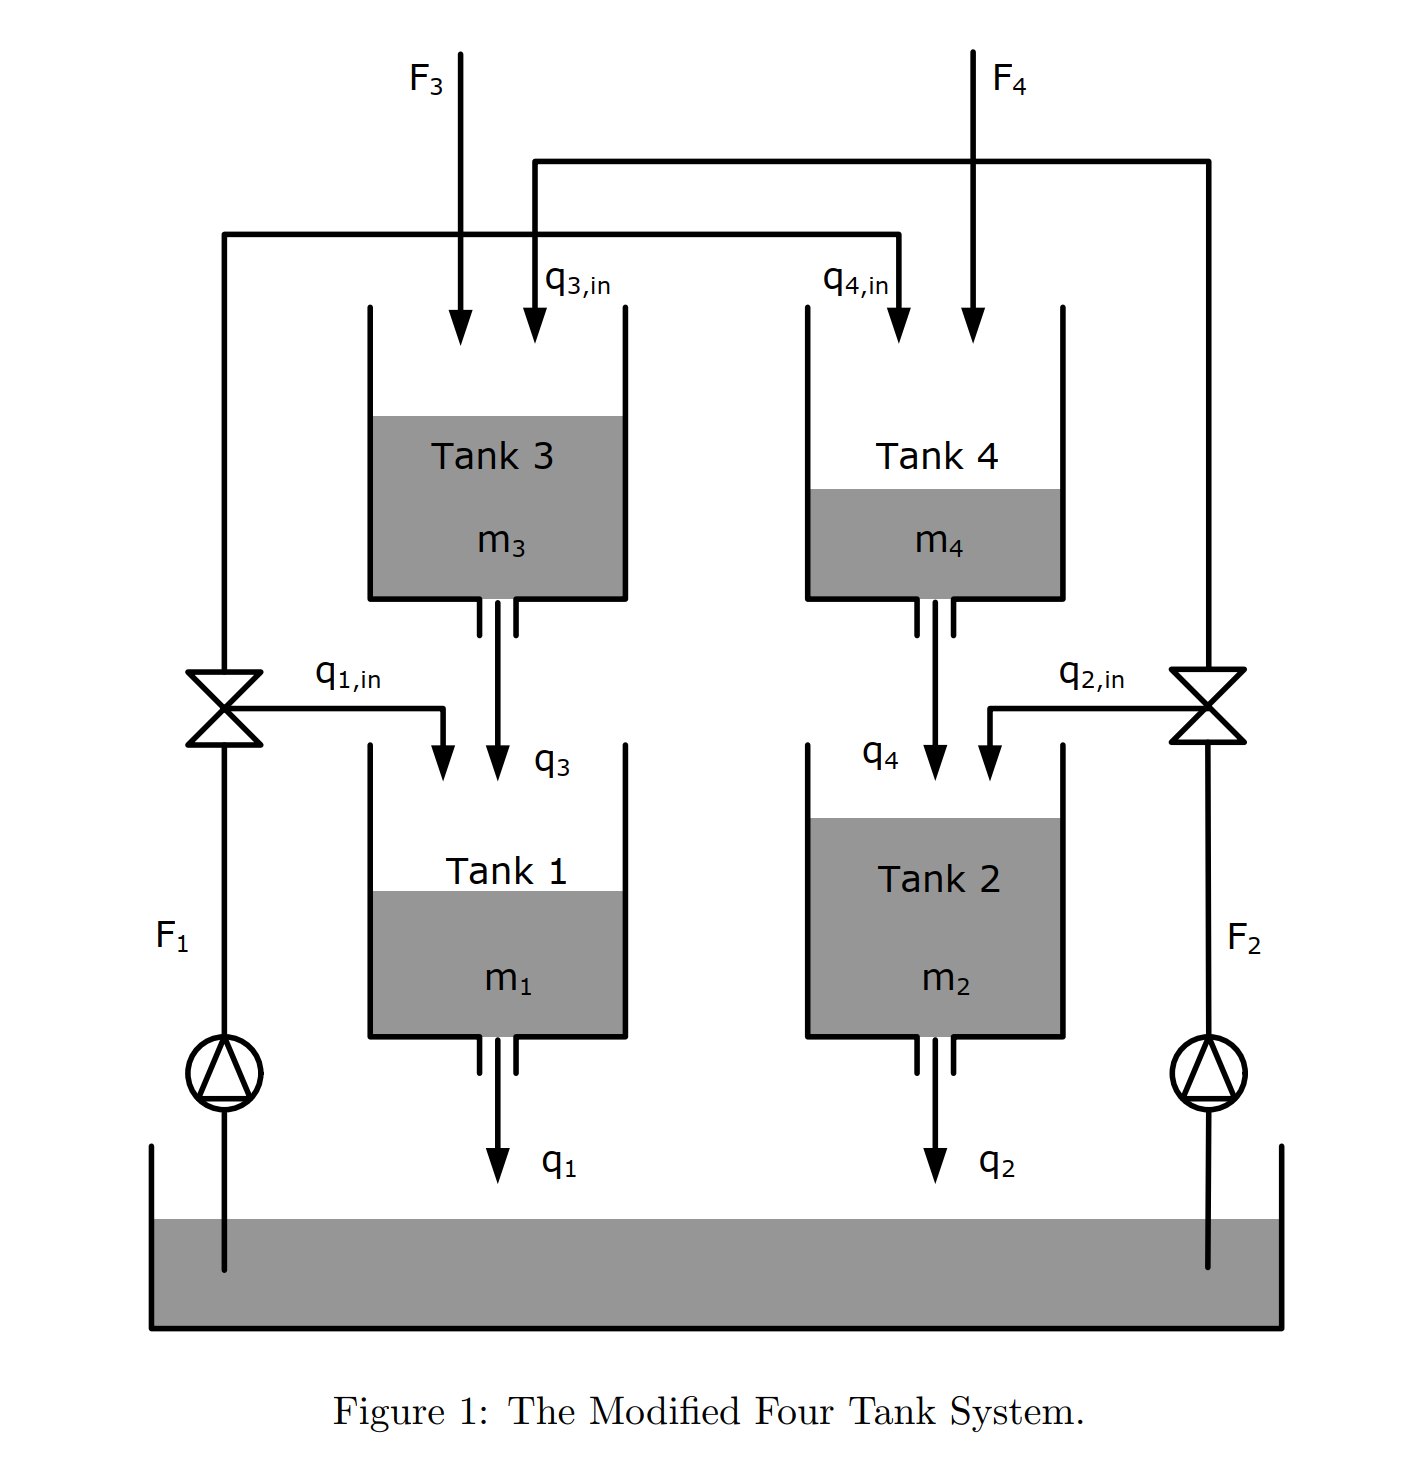

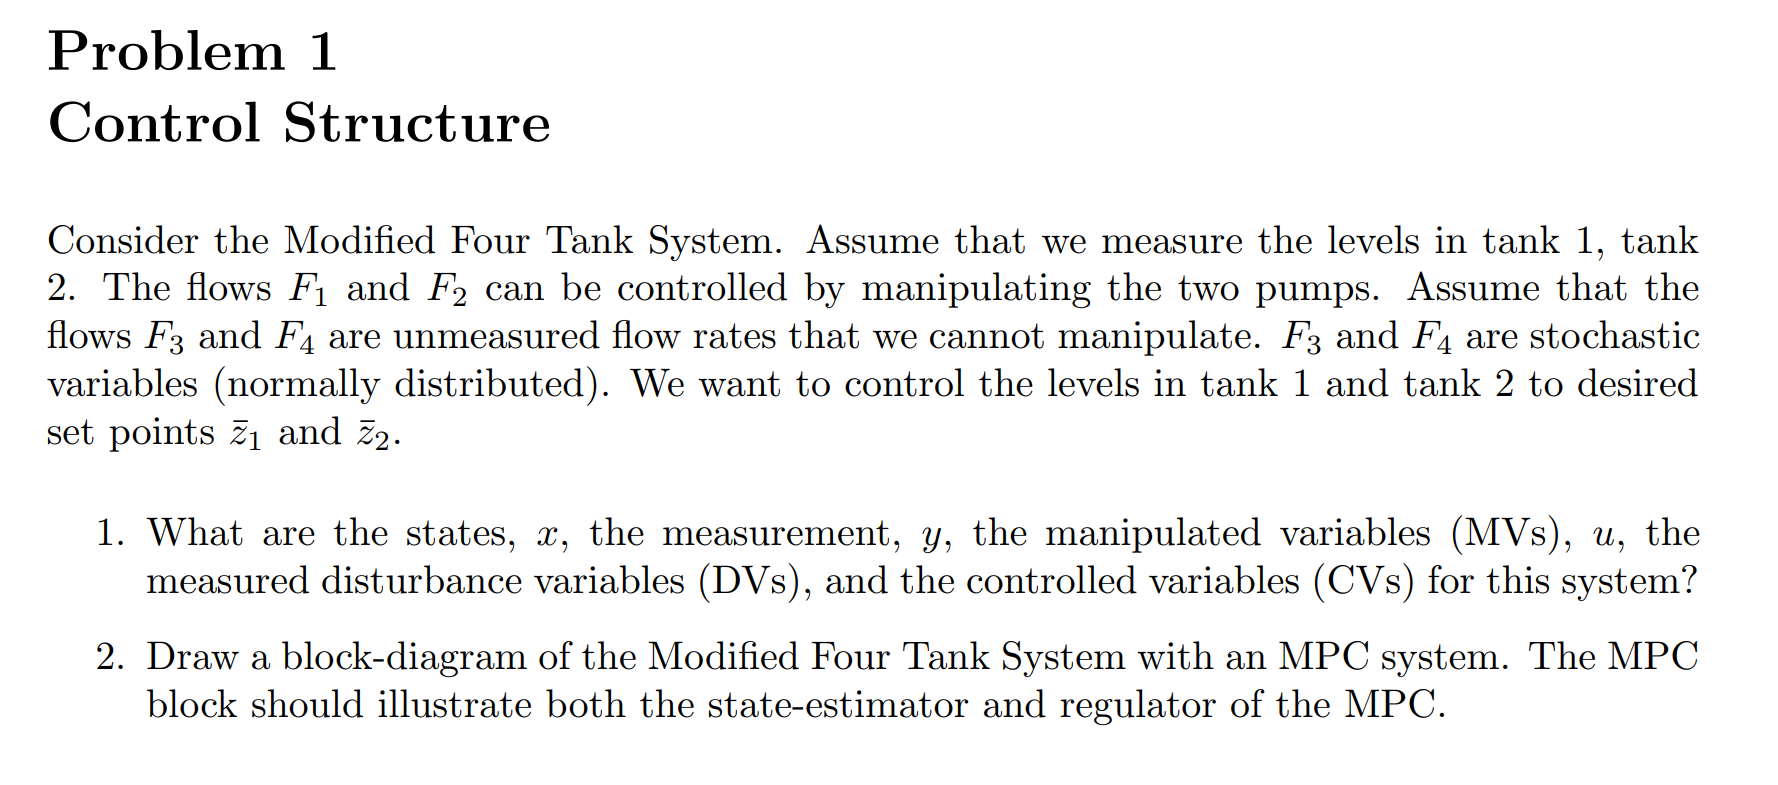

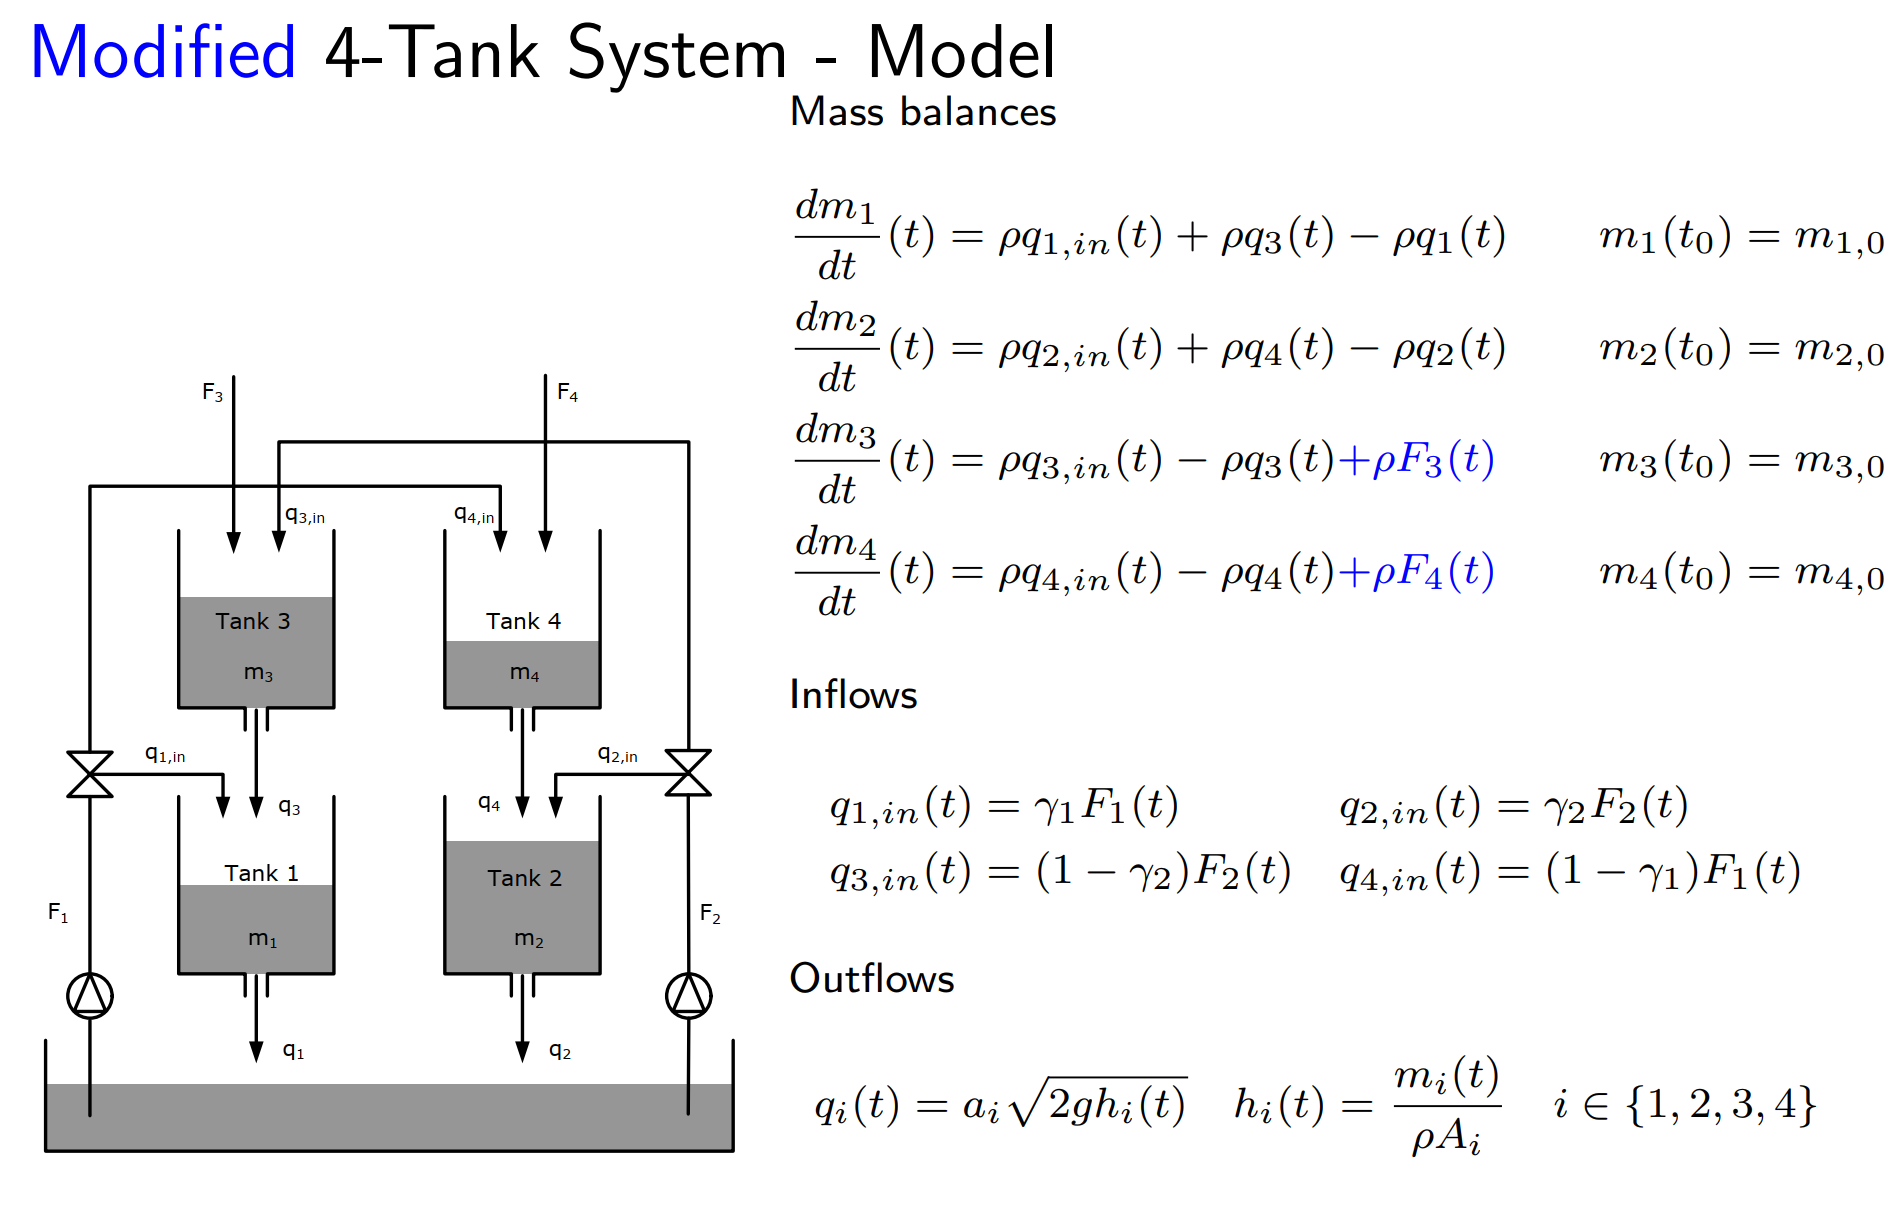

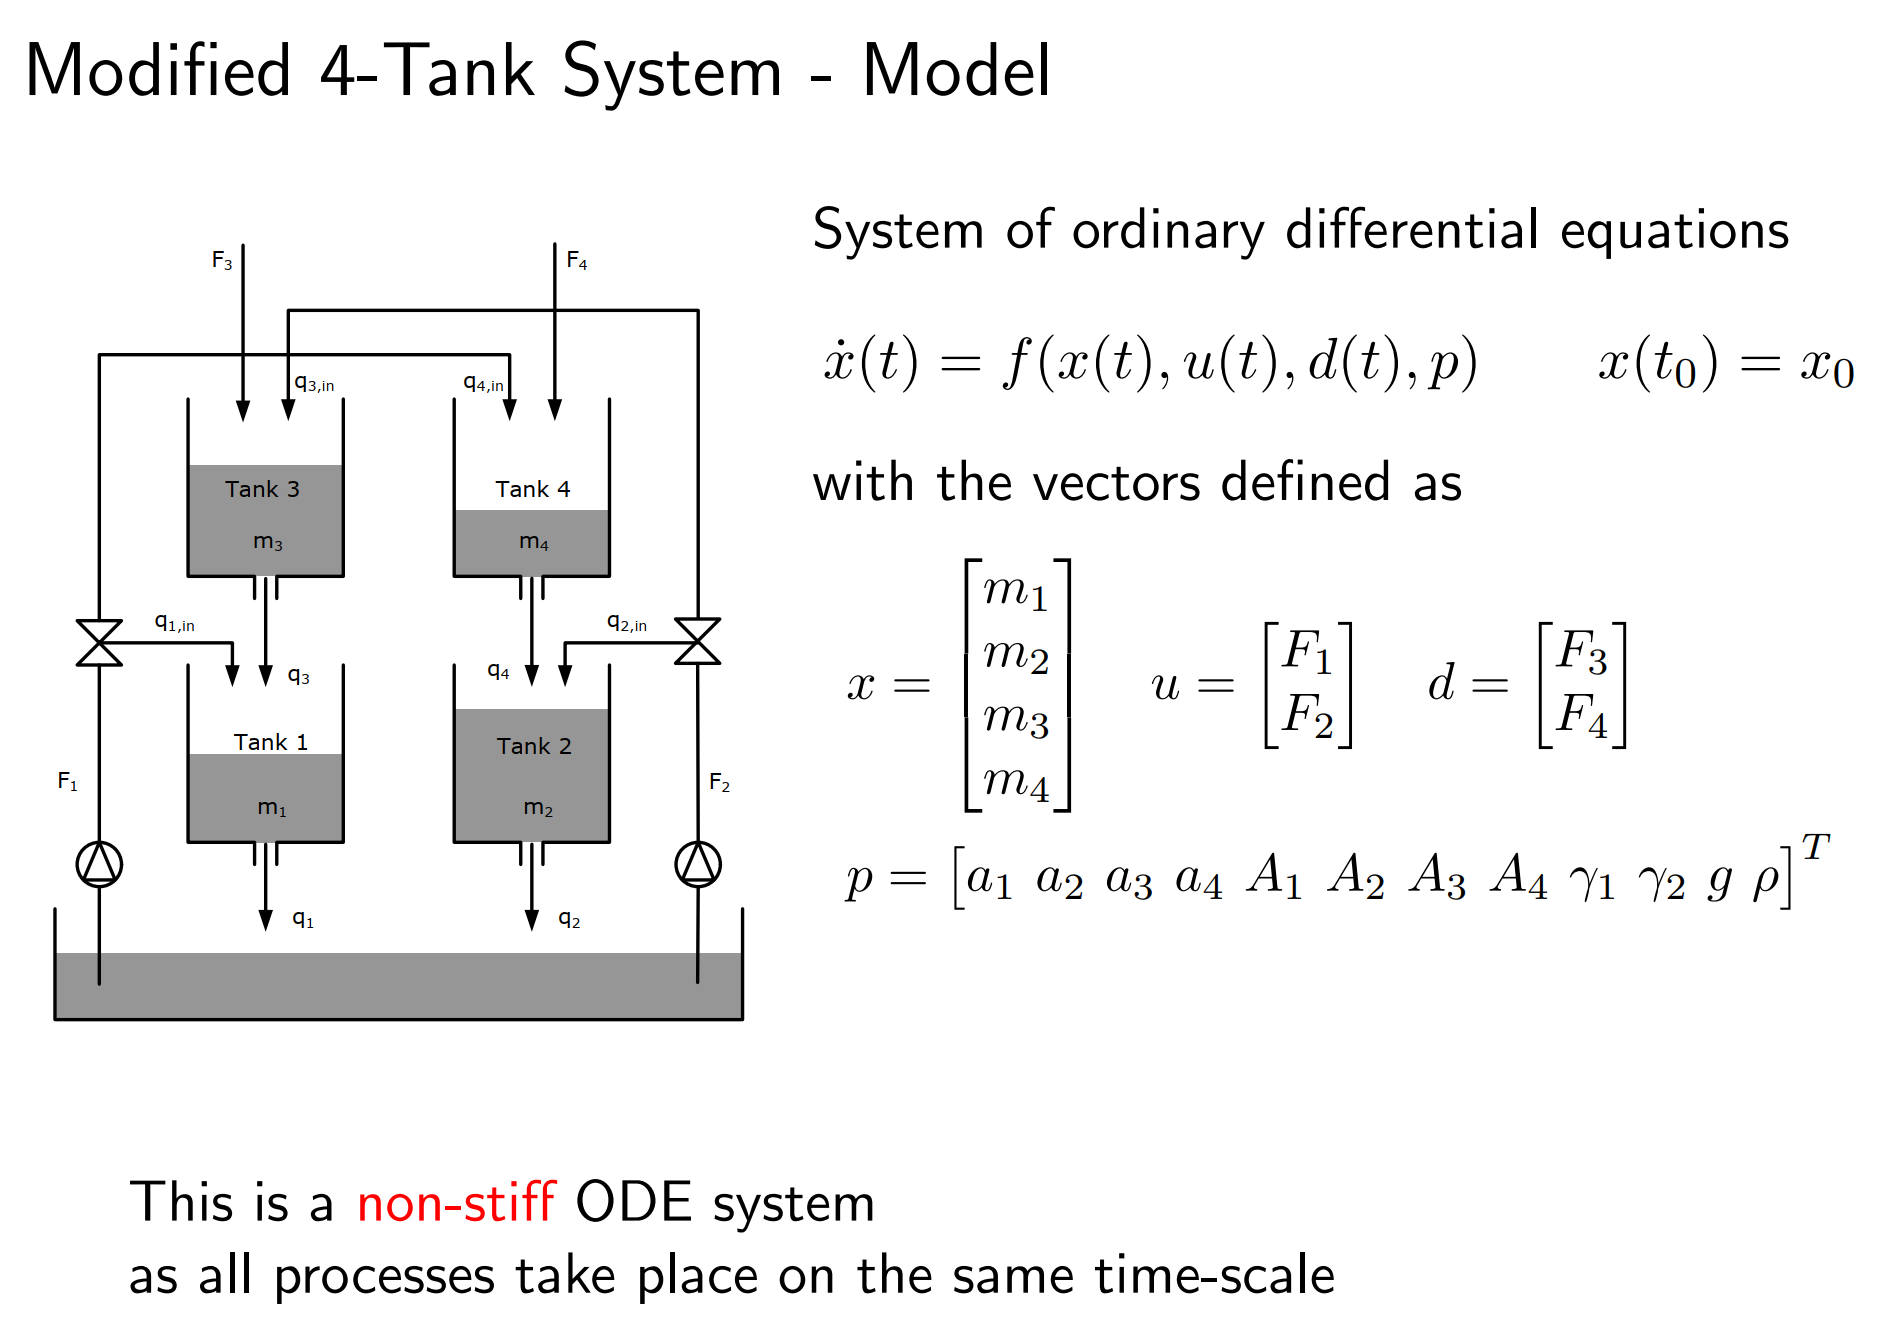

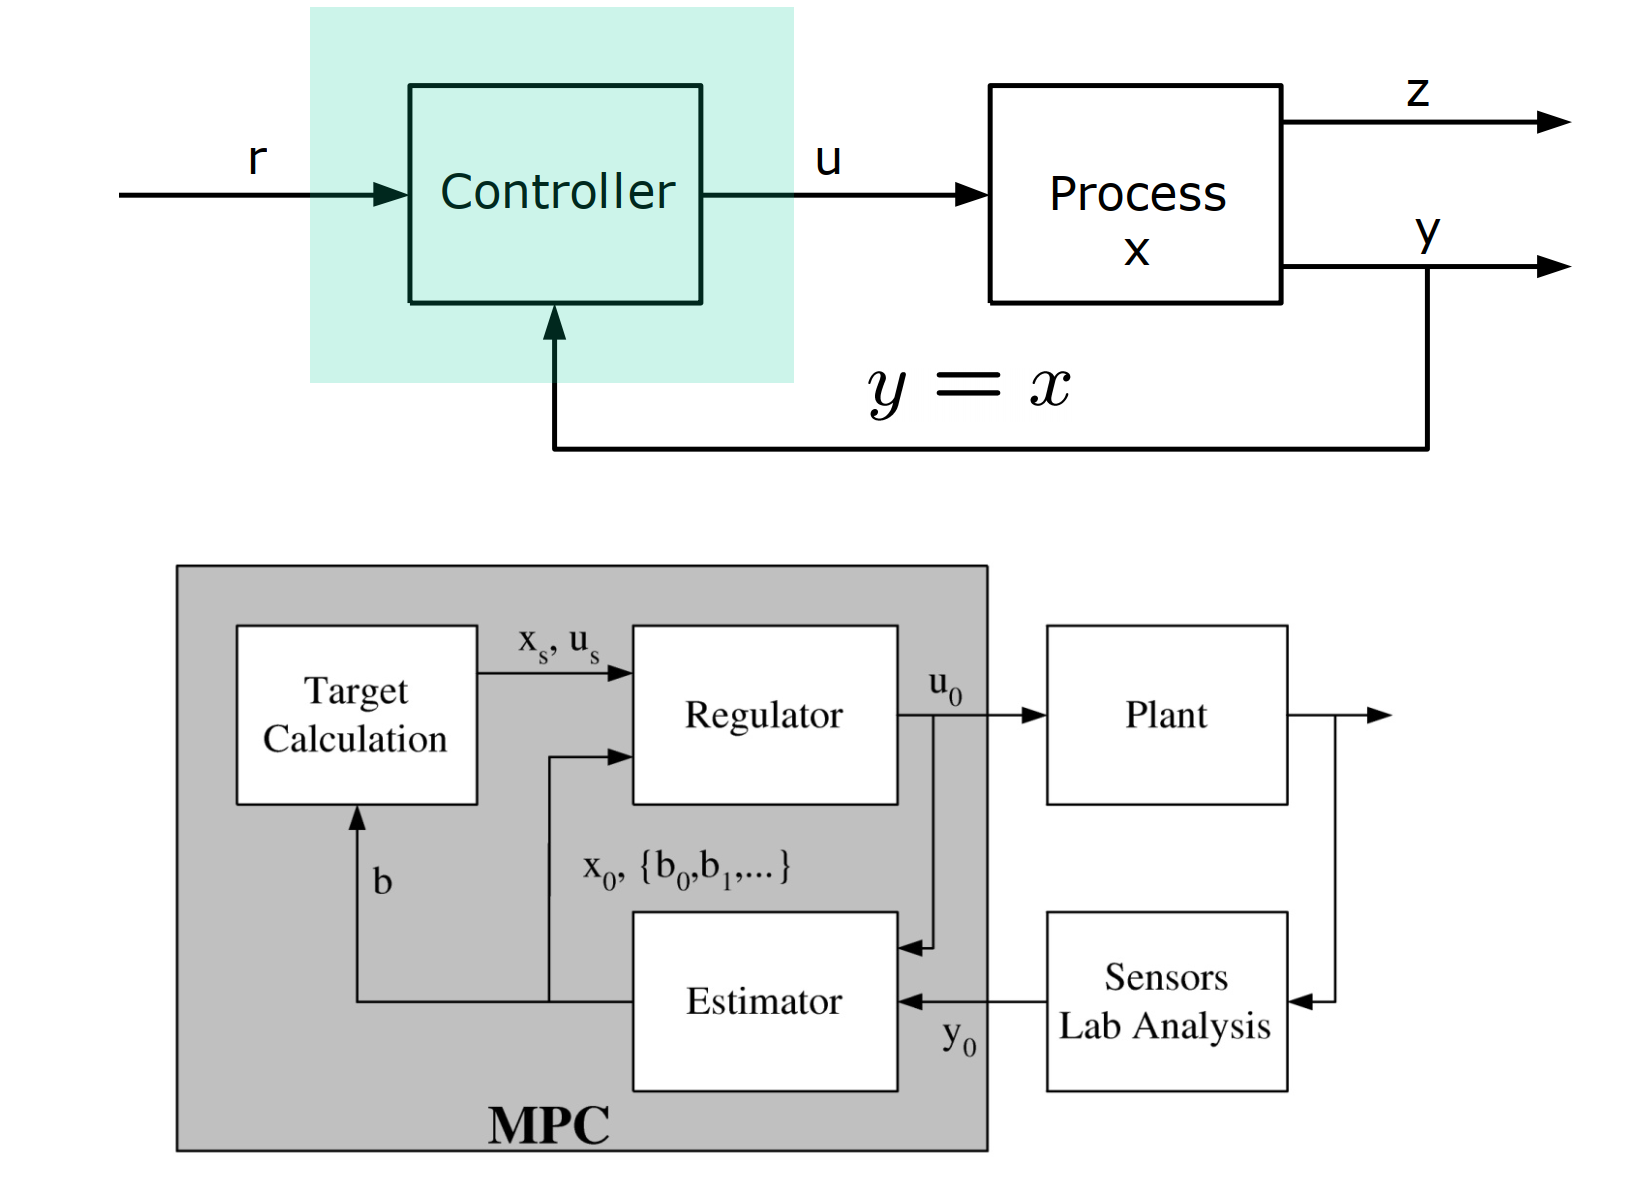

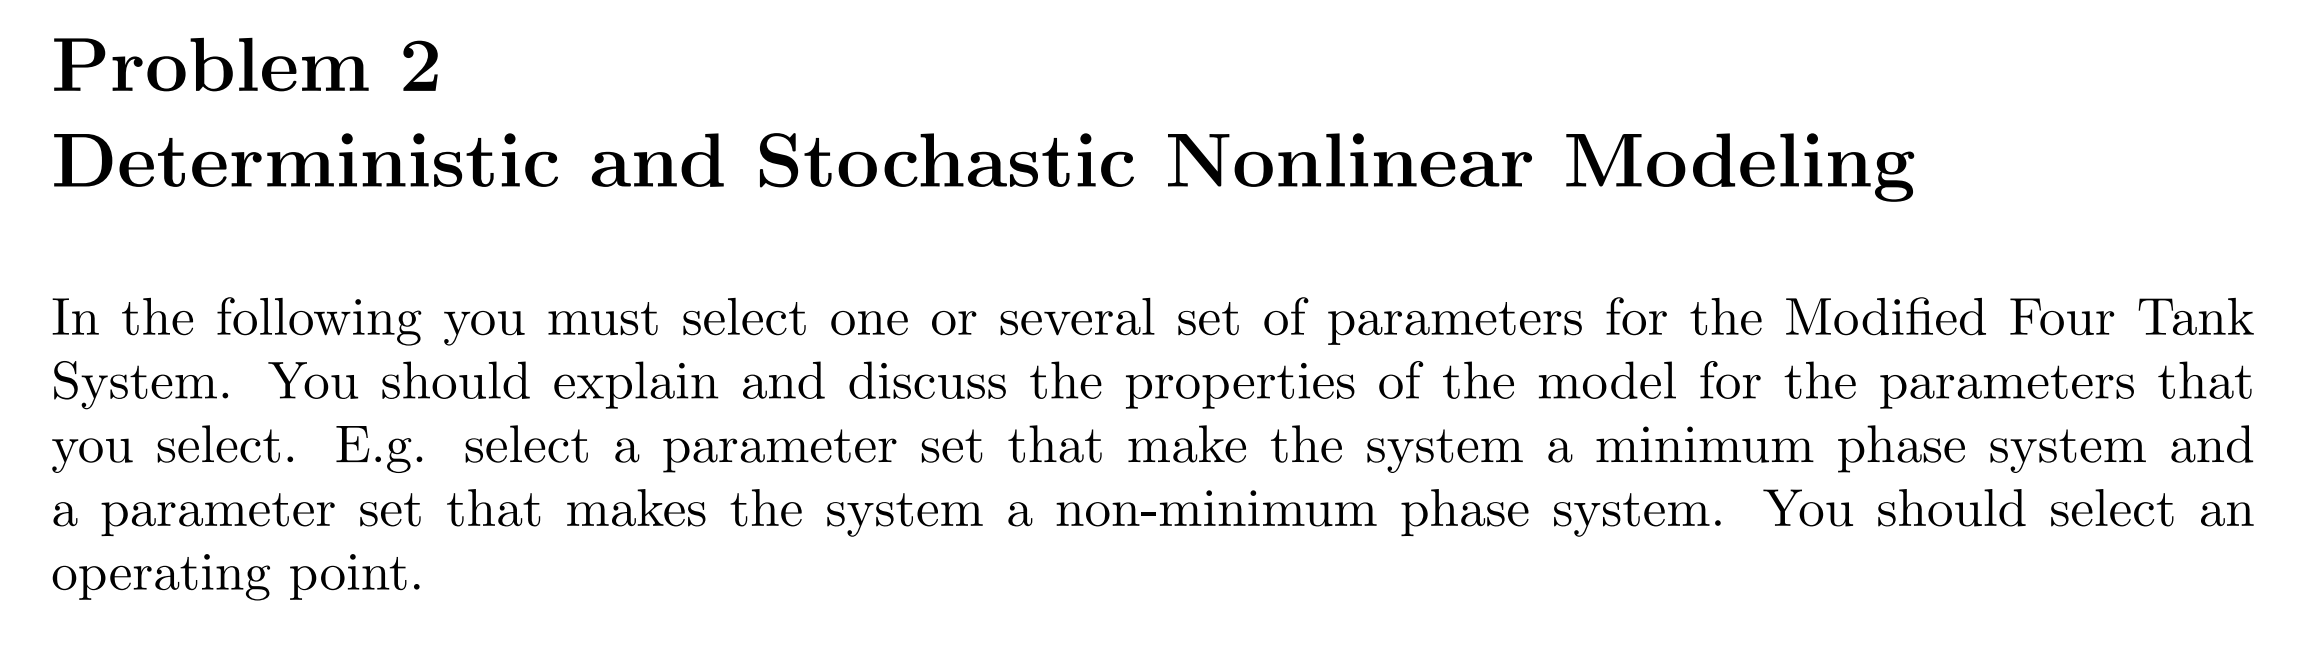

% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------

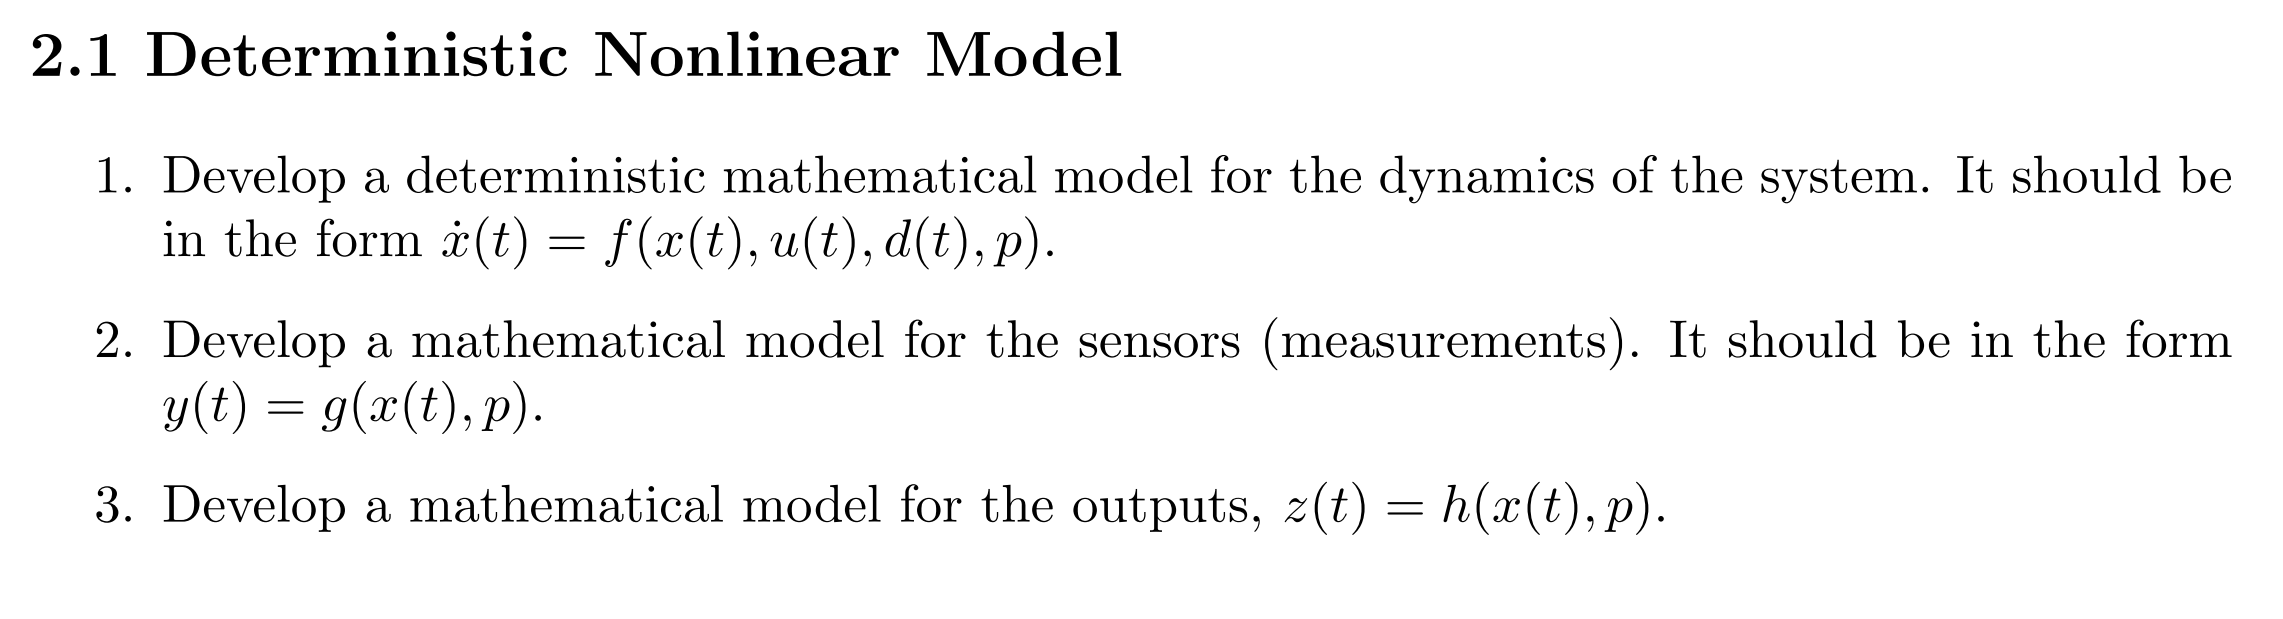

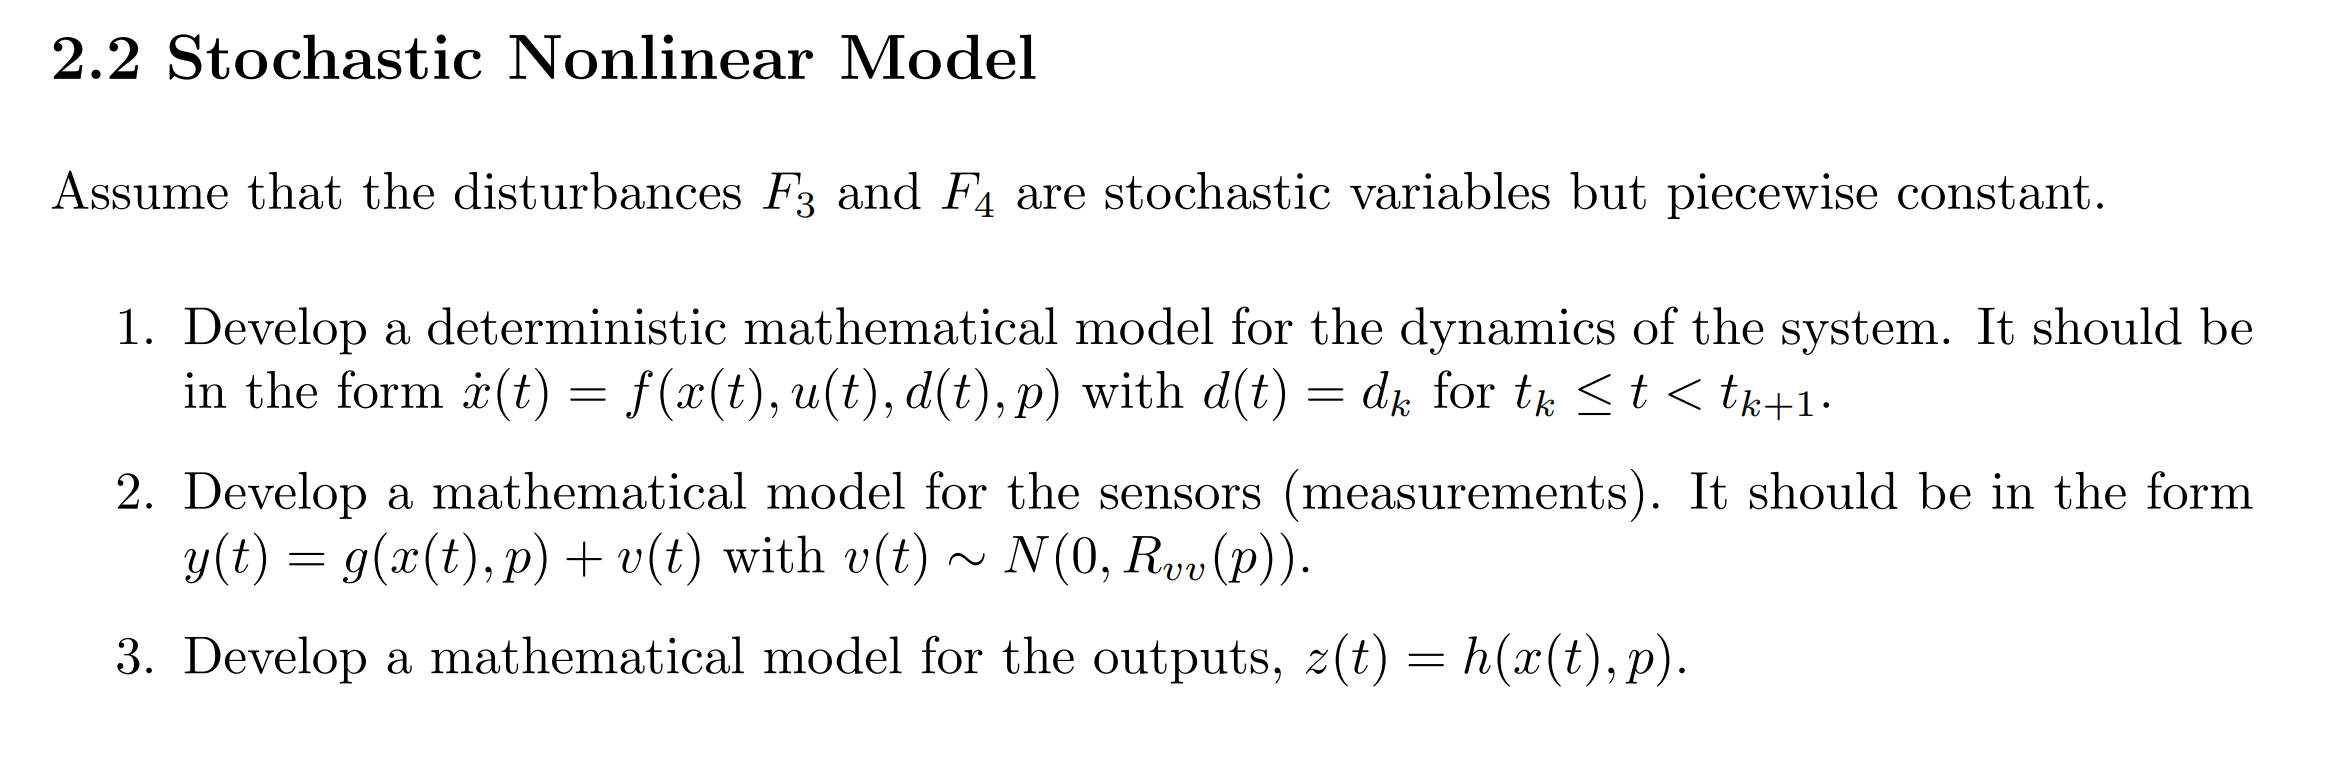

%水箱模型m文件不变，输入的d构造为均值常数的正态分布
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
u = [repmat(F1,1,N); repmat(F2,1,N)];
% Process Noise
Q = [20^2 0;0 40^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);

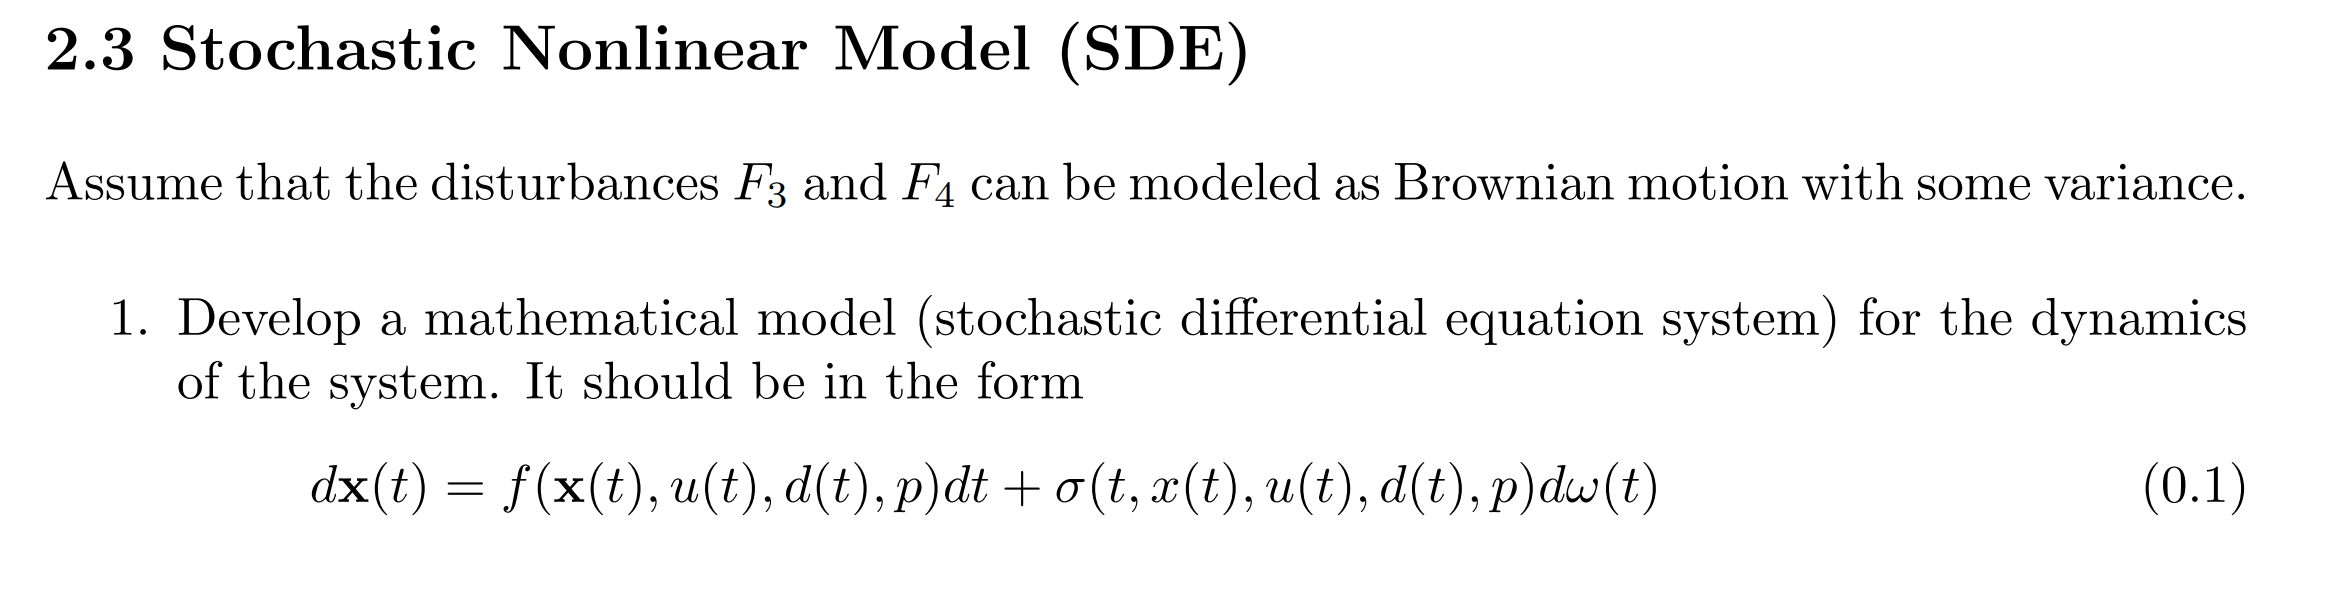

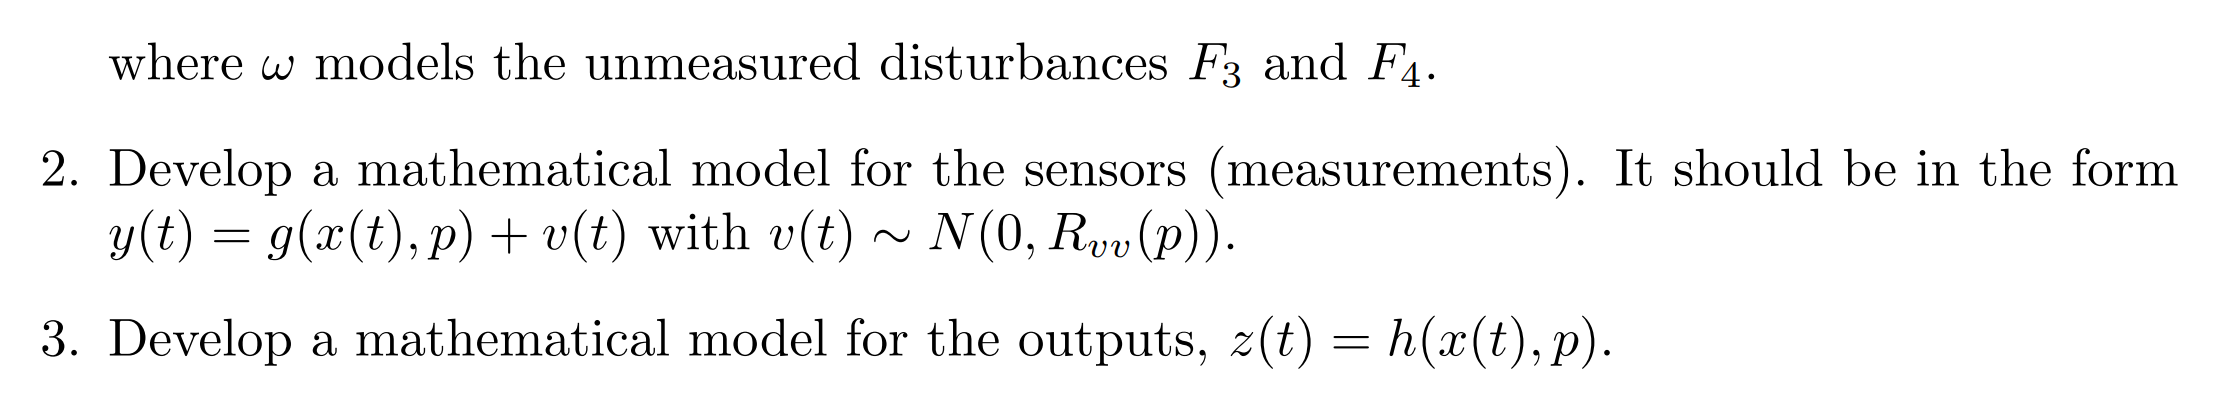

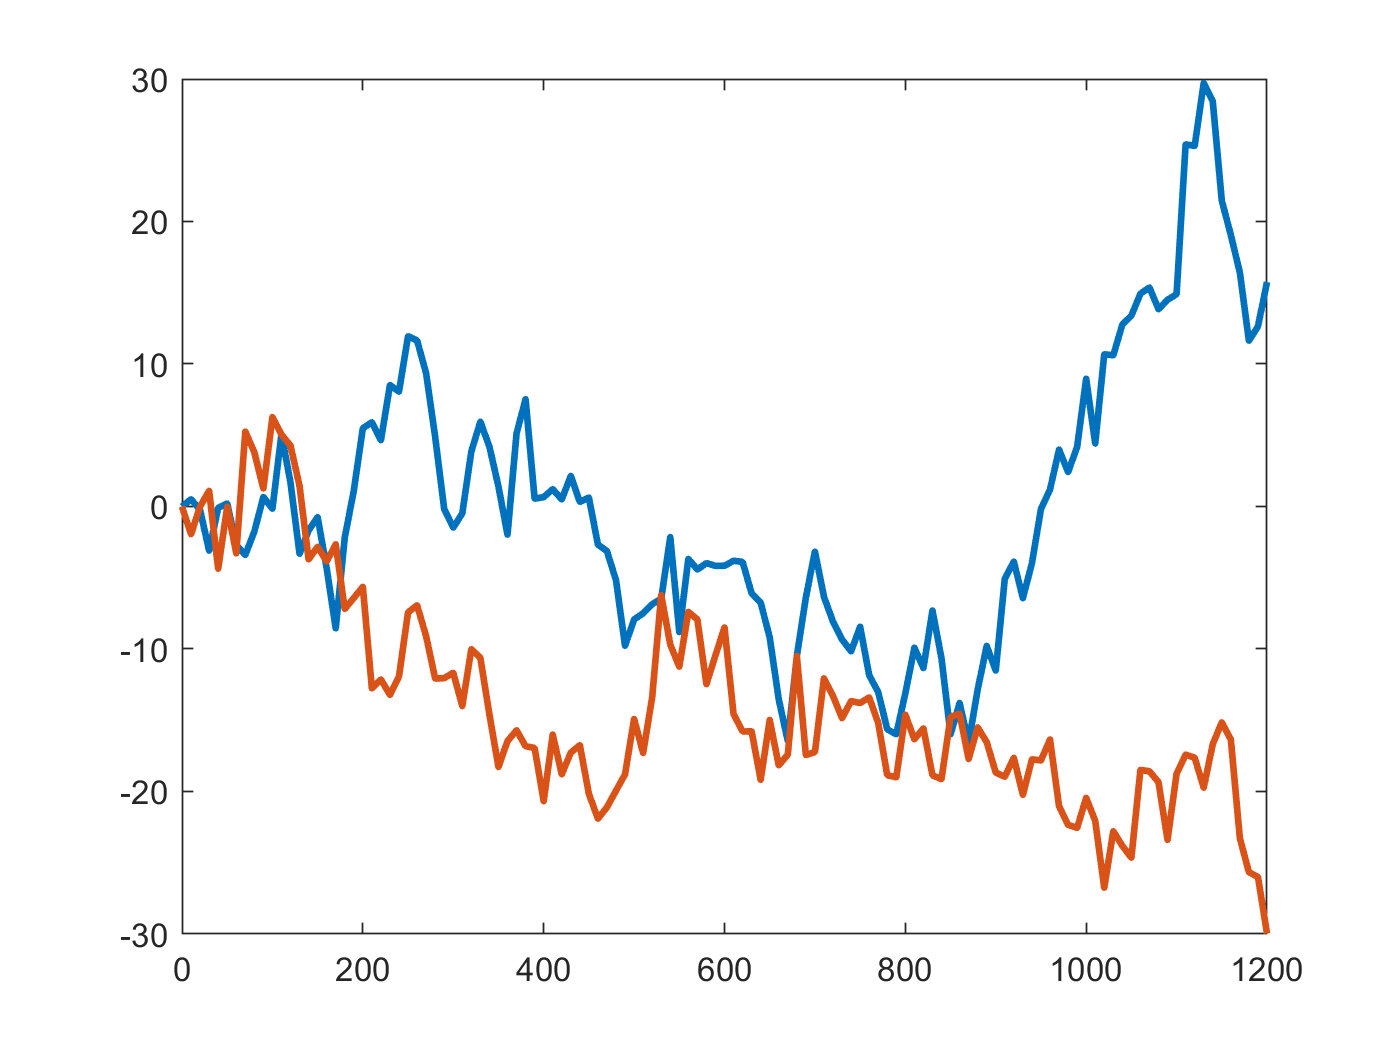

%同样只改变干扰噪音的构造，构造为维纳过程
% Scalar Standard Brownian Motion = Standard Wiener Process
Ns = 2; % Number of realizations
t_final = 20*60; % Final time
Ts=10;
N = t_final/Ts; % Number of time steps
seed = 100; % Seed for reproducibility
[W,Tw,dW] = ScalarStdWienerProcess(t_final,N,Ns,seed);
plot(Tw,W,'linewidth',2)

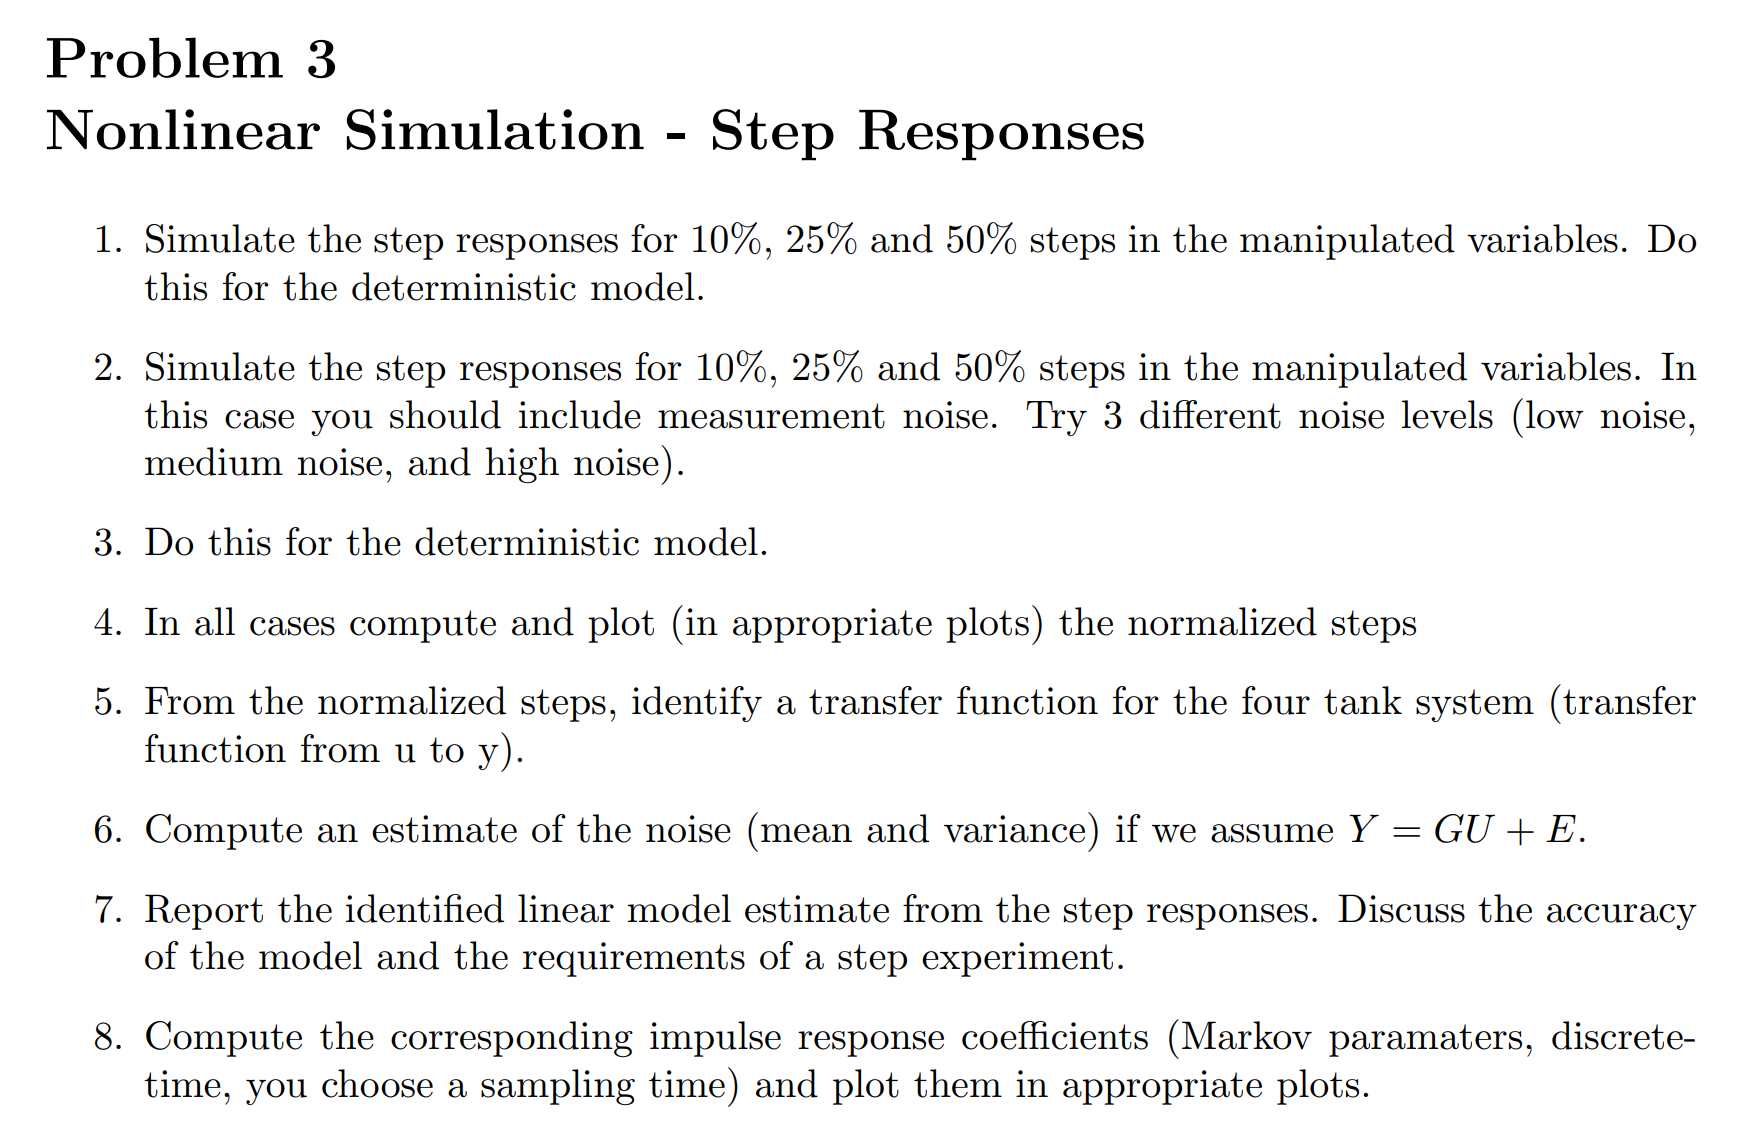

%ex3.1 进行非线性系统的仿真，要用离散的仿真 这里我们每十秒一个区间进行仿真
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
x0 = [m10; m20; m30; m40];
%step 0.05
u_50_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F1(1,40:end)=F1*(1+0.5);
u_50_F2(2,40:end)=F1*(1+0.5);
d = [repmat(F3,1,N); repmat(F4,1,N)];
%step 0.1
u_10 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10(1,40:end)=F1*(1+0.1);
%step 0.25
u_25 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25(1,40:end)=F1*(1+0.25);
% --------------------------------------------------------------
nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;
for k = 1:N-1
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
u_50_F1(:,k),d(:,k),p);
x(:,k+1) = Xk(end,:)';
T = [T; Tk];
X = [X; Xk];
end
k = N;
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function

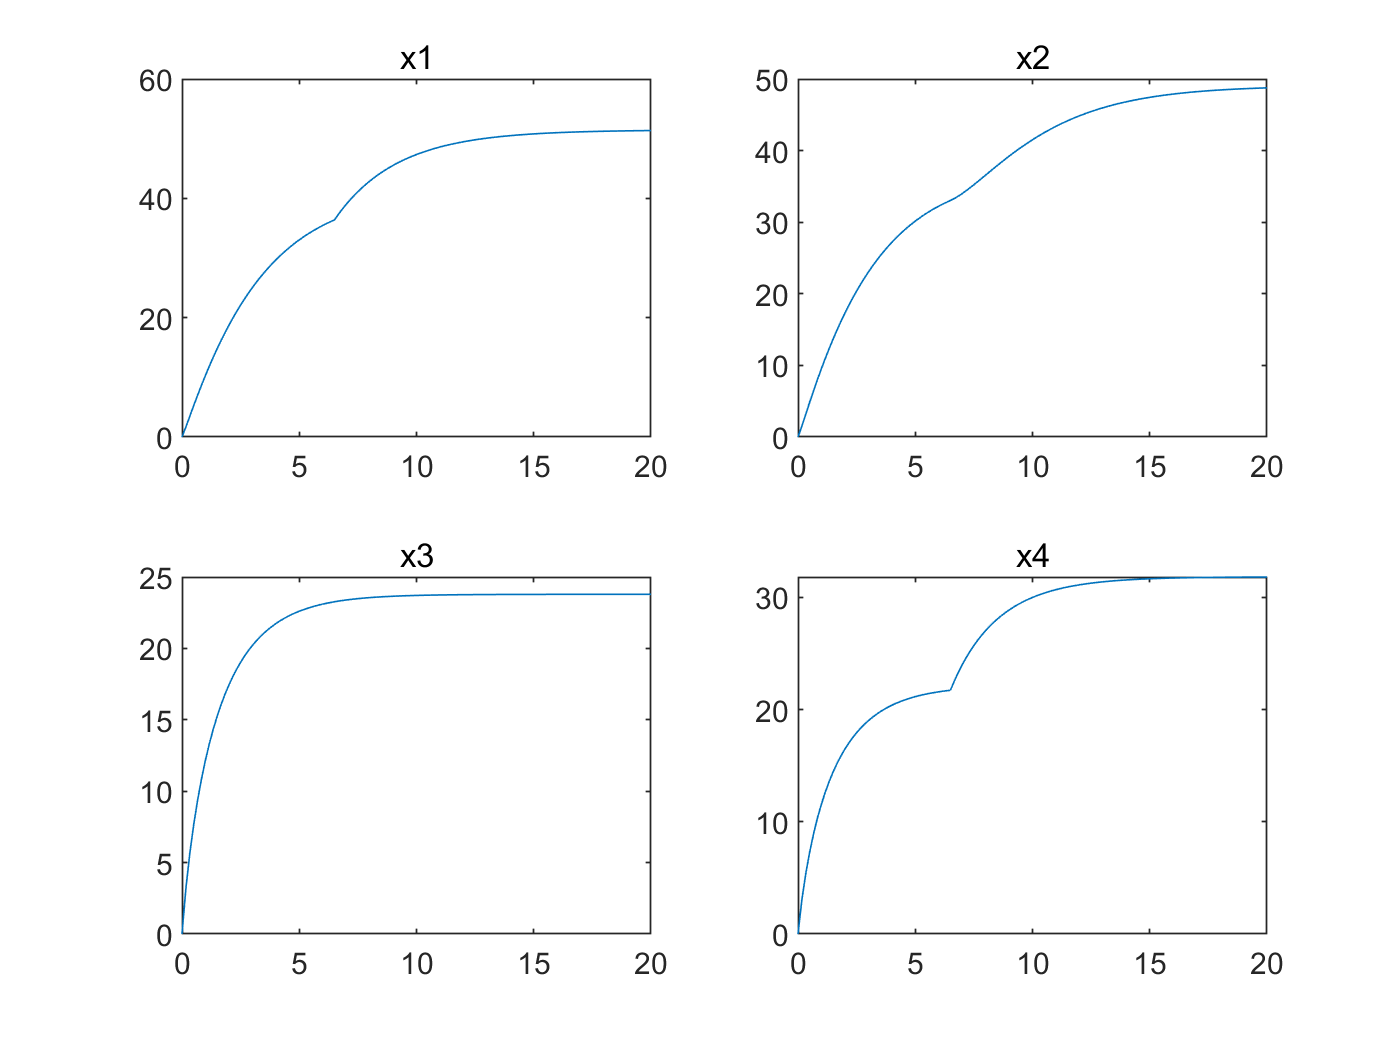

%ex3.1 plot x 
figure
subplot(2,2,1)
plot(t/60,x(1,:)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x(2,:)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x(3,:)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x(4,:)/1e3)
title('x4')

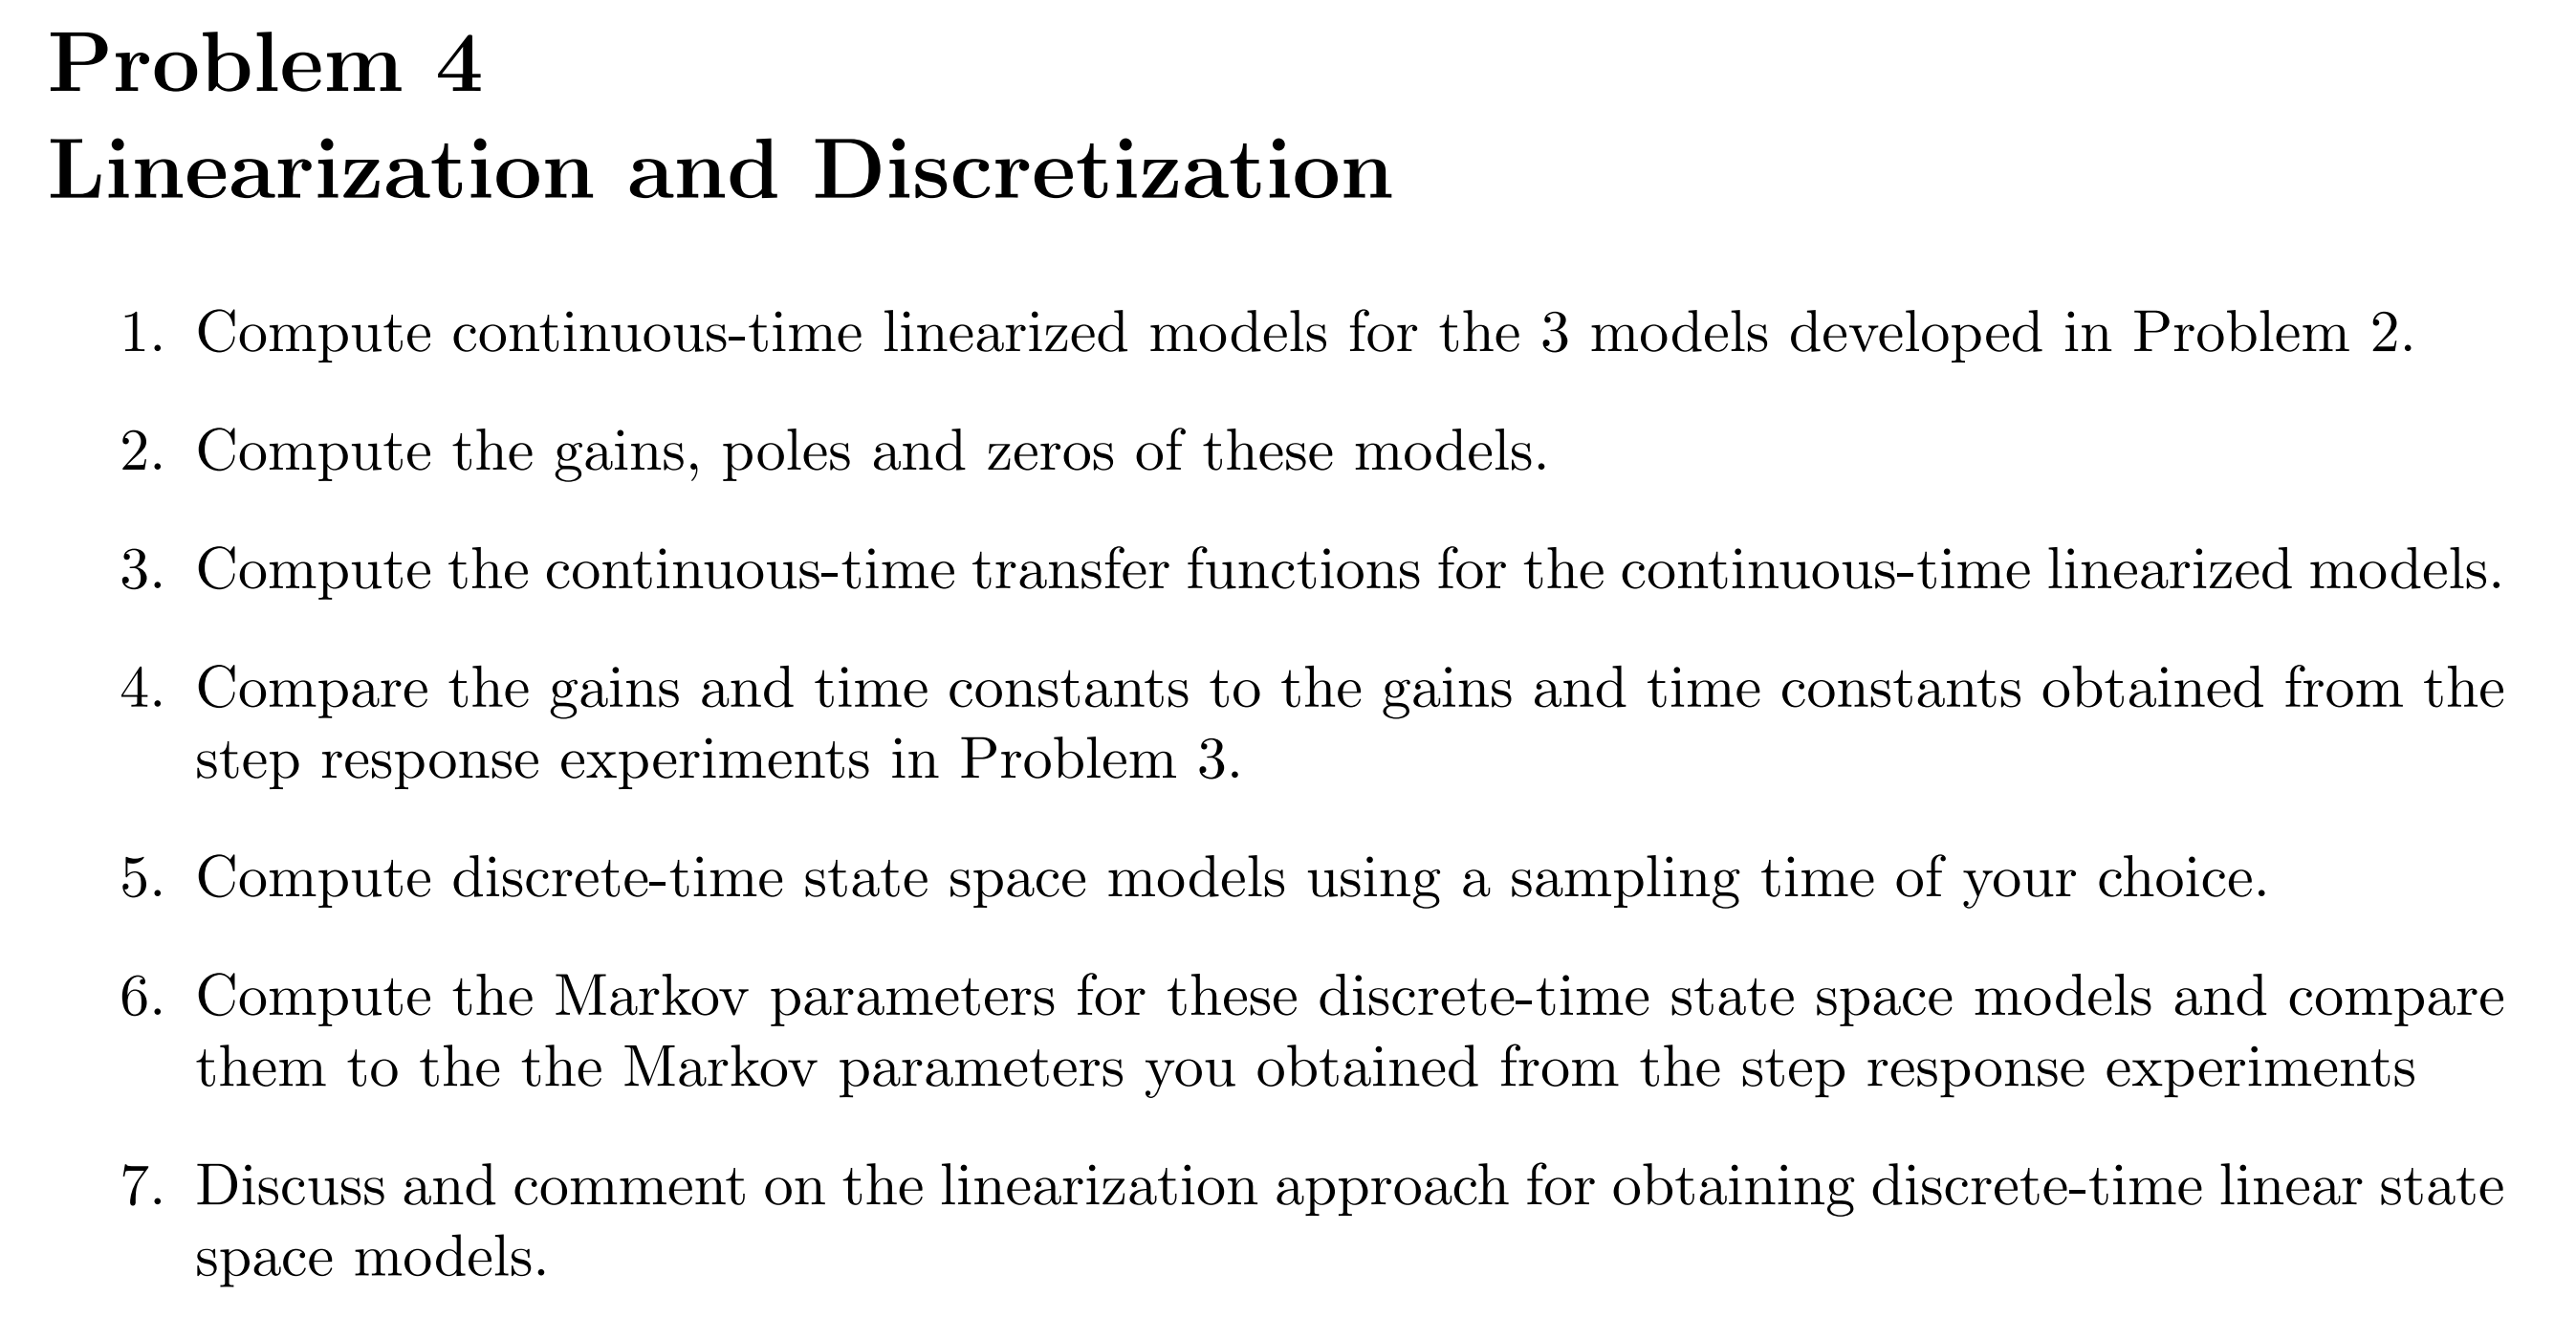

%ex3.1.1 找稳态点，求解非线性方程就可以了，所以使用了fsolve
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F1;F2]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.8658
    4.4027
    2.9641
    2.7817


ys = FourTankSystemSensor(xs,p)

ys =   128.0031
  115.8196
   77.9745
   73.1773


zs = FourTankSystemOutput(xs,p)

zs =   128.0031
  115.8196



%ex3.4.1 对非线性系统进行线性化，需要使用雅可比矩阵求导
syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0063         0    0.0081         0
         0   -0.0066         0    0.0084
         0         0   -0.0081         0
         0         0         0   -0.0084


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0


%ex3.5 线性系统的离散化
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts);
[Ad,Bd_d]=c2dzoh(Ass,Bdss,Ts);

%ex3.6 计算马尔可夫参数，也就是脉冲响应参数
H_0=Dss;
H_1=Css*Bd

H_1 =     0.0047    0.0001
    0.0001    0.0042
         0    0.0062
    0.0057         0


H_2=Css*Ad^1*Bd

H_2 =     0.0046    0.0003
    0.0003    0.0040
         0    0.0060
    0.0055         0


H_3=Css*Ad^2*Bd

H_3 =     0.0044    0.0005
    0.0004    0.0039
         0    0.0058
    0.0053         0


H_4=Css*Ad^3*Bd

H_4 =     0.0043    0.0006
    0.0006    0.0038
         0    0.0056
    0.0051         0


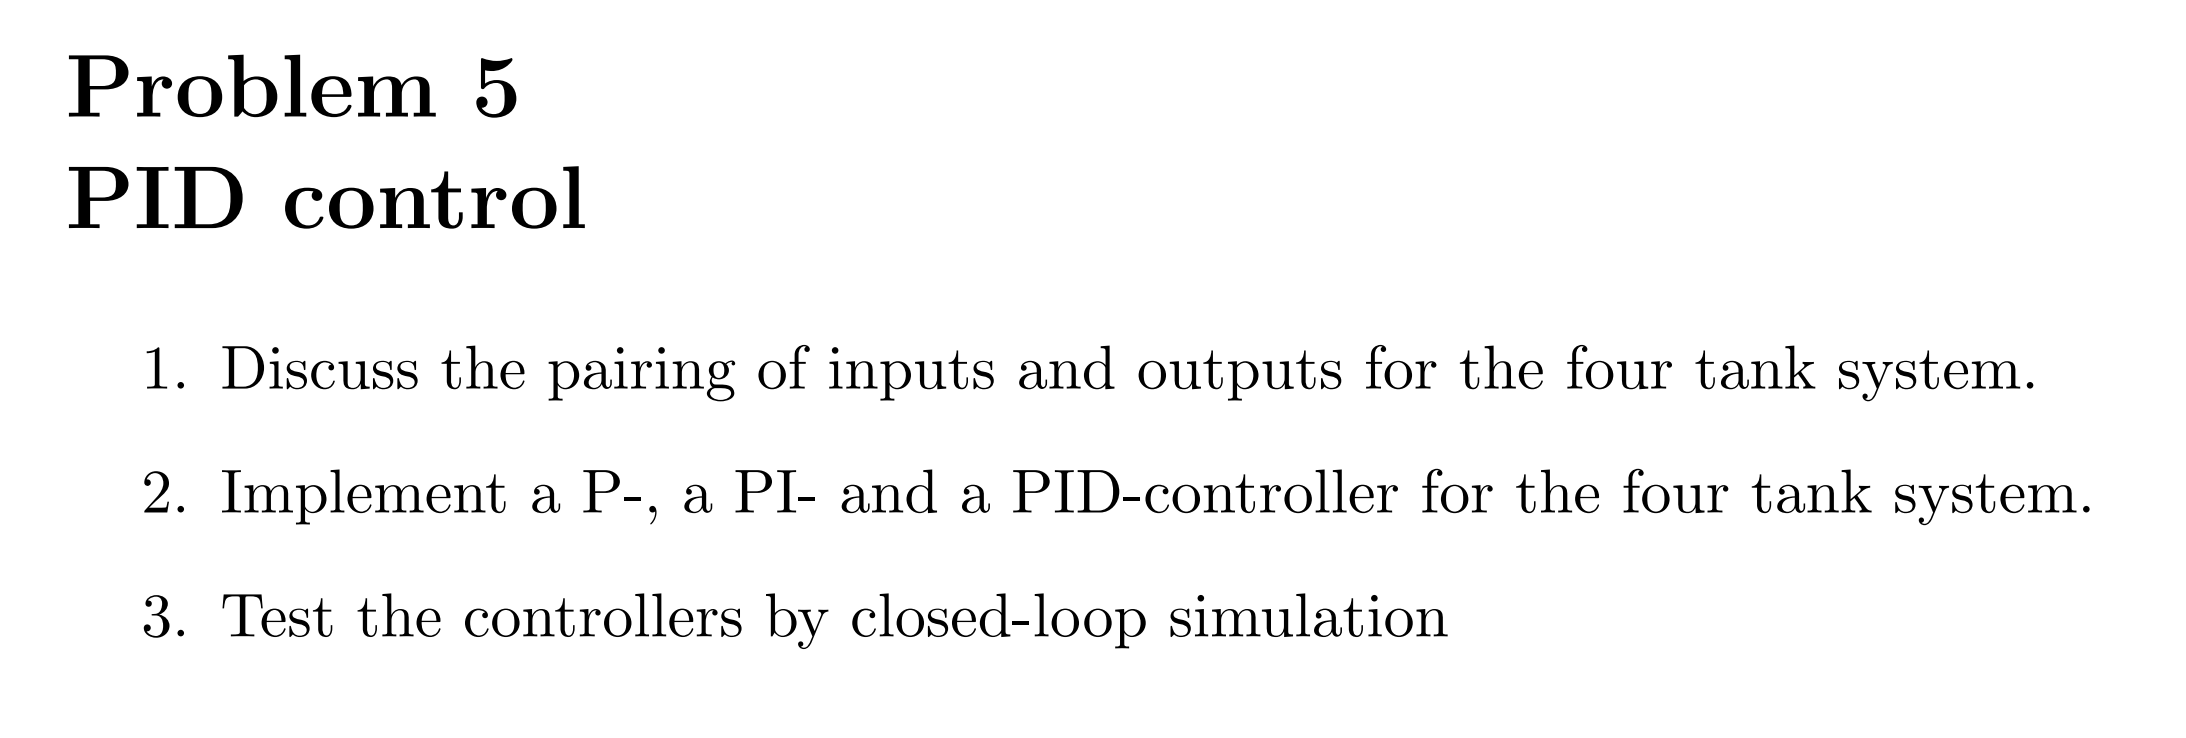

u1->x1,x2,x4

u2->x2,x3

%水箱系统明显是一个MOMO系统，并且还存在着耦合，所以我们需要设计解耦矩阵，然后进行pid的调节
%首先我们需要求出四个传递函数
[num_c_F1,den_c_F1]=ss2tf(Ass,Bss,Css,Dss,1)

num_c_F1 =          0    0.0012    0.0000    0.0000    0.0000
         0         0    0.0000    0.0000    0.0000
         0         0         0         0         0
         0    0.0014    0.0000    0.0000    0.0000


den_c_F1 =     1.0000    0.0294    0.0003    0.0000    0.0000


[num_c_F2,den_c_F2]=ss2tf(Ass,Bss,Css,Dss,2)

num_c_F2 =          0         0    0.0000    0.0000    0.0000
         0    0.0011    0.0000    0.0000    0.0000
         0    0.0016    0.0000    0.0000    0.0000
         0         0         0         0         0


den_c_F2 =     1.0000    0.0294    0.0003    0.0000    0.0000


G_c_F1_y1=tf(num_c_F1(1,:),den_c_F1)%same to con->dis

G_c_F1_y1 =
 
    0.001184 s^3 + 2.735e-05 s^2 + 2.096e-07 s + 5.323e-10
  ----------------------------------------------------------
  s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
Continuous-time transfer function.



G_c_F1_y2=tf(num_c_F1(2,:),den_c_F1)

G_c_F1_y2 =
 
           1.209e-05 s^2 + 1.744e-07 s + 6.189e-10
  ----------------------------------------------------------
  s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
Continuous-time transfer function.



G_c_F2_y1=tf(num_c_F2(1,:),den_c_F2)

G_c_F2_y1 =
 
           1.278e-05 s^2 + 1.918e-07 s + 7.098e-10
  ----------------------------------------------------------
  s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
Continuous-time transfer function.



G_c_F2_y2=tf(num_c_F2(2,:),den_c_F2)

G_c_F2_y2 =
 
    0.001052 s^3 + 2.397e-05 s^2 + 1.807e-07 s + 4.501e-10
  ----------------------------------------------------------
  s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
Continuous-time transfer function.




[num_d_F1,den_d_F1]=ss2tf(Ad,Bd,Css,Dss,1)

num_d_F1 =          0    0.0047   -0.0136    0.0132   -0.0043
         0    0.0001   -0.0001   -0.0001    0.0001
         0         0         0         0         0
         0    0.0057   -0.0166    0.0161   -0.0052


den_d_F1 =     1.0000   -3.8841    5.6572   -3.6621    0.8890


[num_d_F2,den_d_F2]=ss2tf(Ad,Bd,Css,Dss,2)

num_d_F2 =          0    0.0001   -0.0001   -0.0001    0.0001
         0    0.0042   -0.0121    0.0117   -0.0038
         0    0.0062   -0.0181    0.0176   -0.0057
         0         0         0         0         0


den_d_F2 =     1.0000   -3.8841    5.6572   -3.6621    0.8890


G_d_F1_y1=tf(num_d_F1(1,:),den_d_F1,Ts)%same to con->dis

G_d_F1_y1 =
 
  0.004676 z^3 - 0.0136 z^2 + 0.01319 z - 0.004264
  ------------------------------------------------
   z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F1_y2=tf(num_d_F1(2,:),den_d_F1,Ts)

G_d_F1_y2 =
 
  9.484e-05 z^3 - 9.133e-05 z^2 - 9.112e-05 z + 8.775e-05
  -------------------------------------------------------
       z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F2_y1=tf(num_d_F2(1,:),den_d_F2,Ts)

G_d_F2_y1 =
 
  0.0001003 z^3 - 9.629e-05 z^2 - 9.652e-05 z + 9.267e-05
  -------------------------------------------------------
       z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F2_y2=tf(num_d_F2(2,:),den_d_F2,Ts)

G_d_F2_y2 =
 
  0.004154 z^3 - 0.01209 z^2 + 0.01173 z - 0.003792
  -------------------------------------------------
    z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
Sample time: 4 seconds
Discrete-time transfer function.




G_MIMO=[G_d_F1_y1,G_d_F1_y2;G_d_F2_y1,G_d_F2_y2]

G_MIMO =
 
  From input 1 to output...
       0.004676 z^3 - 0.0136 z^2 + 0.01319 z - 0.004264
   1:  ------------------------------------------------
        z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
       0.0001003 z^3 - 9.629e-05 z^2 - 9.652e-05 z + 9.267e-05
   2:  -------------------------------------------------------
            z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
  From input 2 to output...
       9.484e-05 z^3 - 9.133e-05 z^2 - 9.112e-05 z + 8.775e-05
   1:  -------------------------------------------------------
            z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
       0.004154 z^3 - 0.01209 z^2 + 0.01173 z - 0.003792
   2:  -------------------------------------------------
         z^4 - 3.884 z^3 + 5.657 z^2 - 3.662 z + 0.889
 
Sample time: 4 seconds
Discrete-time transfer function.



G_c_MIMO=[G_c_F1_y1,G_c_F1_y2;G_c_F2_y1,G_c_F2_y2]

G_c_MIMO =
 
  From input 1 to output...
         0.001184 s^3 + 2.735e-05 s^2 + 2.096e-07 s + 5.323e-10
   1:  ----------------------------------------------------------
       s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
                1.278e-05 s^2 + 1.918e-07 s + 7.098e-10
   2:  ----------------------------------------------------------
       s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
  From input 2 to output...
                1.209e-05 s^2 + 1.744e-07 s + 6.189e-10
   1:  ----------------------------------------------------------
       s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
         0.001052 s^3 + 2.397e-05 s^2 + 1.807e-07 s + 4.501e-10
   2:  ----------------------------------------------------------
       s^4 + 0.02942 s^3 + 0.000323 s^2 + 1.568e-06 s + 2.842e-09
 
Continuous-time transfer function.



%我们使用静态解耦矩阵计算
G0_MIMO=dcgain(G_MIMO)

G0_11 = -0.0048

G0_12 = 9.8713e-05

G0_21 = 1.0424e-04

G0_22 = -0.0043

G0_MIMO =     0.1873    0.2178
    0.2498    0.1584


G0_c_11=dcgain(cell2mat(G_c_F1_y1.Numerator),cell2mat(G_c_F1_y1.Denominator))

G0_c_11 = 0.1873

G0_c_12=dcgain(cell2mat(G_c_F1_y2.Numerator),cell2mat(G_c_F1_y2.Denominator))

G0_c_12 = 0.2178

G0_c_21=dcgain(cell2mat(G_c_F2_y1.Numerator),cell2mat(G_c_F2_y1.Denominator))

G0_c_21 = 0.2498

G0_c_22=dcgain(cell2mat(G_c_F2_y2.Numerator),cell2mat(G_c_F2_y2.Denominator))

G0_c_22 = 0.1584

G0_c_MIMO=dcgain(G_c_MIMO)%just for test

G0_c_MIMO =     0.1873    0.2178
    0.2498    0.1584


%计算相对增益矩阵，判断是否需要进行解耦操作
F0=G0_MIMO(1,2)*G0_MIMO(2,1)/(G0_MIMO(1,1)*G0_MIMO(2,2))

F0 = 1.8333

T0_11=1/(1-F0)

T0_11 = -1.2000

T0_12=-F0/(1-F0)

T0_12 = 2.2000

T0_21=-F0/(1-F0)

T0_21 = 2.2000

T0_22=1/(1-F0)

T0_22 = -1.2000

%计算静态解耦矩阵
G0_11=G0_MIMO(1,1);
G0_12=G0_MIMO(1,2);
G0_21=G0_MIMO(2,1);
G0_22=G0_MIMO(2,2);
D0=(1/(G0_11*G0_22-G0_12*G0_21))*[G0_22*G0_11,-G0_12*G0_22;-G0_21*G0_11,G0_11*G0_22]

D0 =    -1.2000    1.3951
    1.8923   -1.2000


%TEST 解耦矩阵
G_MIMO_decop=D0*G_MIMO

G_MIMO_decop =
 
  From input 1 to output...
       -0.005472 z^7 + 0.03744 z^6 - 0.1098 z^5 + 0.1789 z^4 - 0.1748 z^3 + 0.1025 z^2 - 0.0334 z + 0.004663
   1:  -----------------------------------------------------------------------------------------------------
           z^8 - 7.768 z^7 + 26.4 z^6 - 51.27 z^5 + 62.23 z^4 - 48.34 z^3 + 23.47 z^2 - 6.511 z + 0.7903
 
       0.008729 z^7 - 0.05953 z^6 + 0.174 z^5 - 0.2825 z^4 + 0.2752 z^3 - 0.1609 z^2 + 0.05225 z - 0.007271
   2:  ----------------------------------------------------------------------------------------------------
          z^8 - 7.768 z^7 + 26.4 z^6 - 51.27 z^5 + 62.23 z^4 - 48.34 z^3 + 23.47 z^2 - 6.511 z + 0.7903
 
  From input 2 to output...
       0.005682 z^7 - 0.03883 z^6 + 0.1137 z^5 - 0.185 z^4 + 0.1806 z^3 - 0.1057 z^2 + 0.03441 z - 0.004797
   1:  ----------------------------------------------------------------------------------------------------
          z^8 - 7.768 z^7 + 26.4 z^6 - 51.27 z^5 + 62.23 z^4 - 4

G0_MIMO_decop=dcgain(G_MIMO_decop)

G0_MIMO_decop =     0.1179   -0.0385
    0.0521    0.2117


F0_decop=G0_MIMO_decop(1,2)*G0_MIMO_decop(2,1)/(G0_MIMO_decop(1,1)*G0_MIMO_decop(2,2))

F0_decop = -0.0805

T0_11_decop=1/(1-F0_decop)

T0_11_decop = 0.9255

T0_12_decop=-F0_decop/(1-F0_decop)

T0_12_decop = 0.0745

T0_21_decop=-F0_decop/(1-F0_decop)

T0_21_decop = 0.0745

T0_22_decop=1/(1-F0_decop)

T0_22_decop = 0.9255

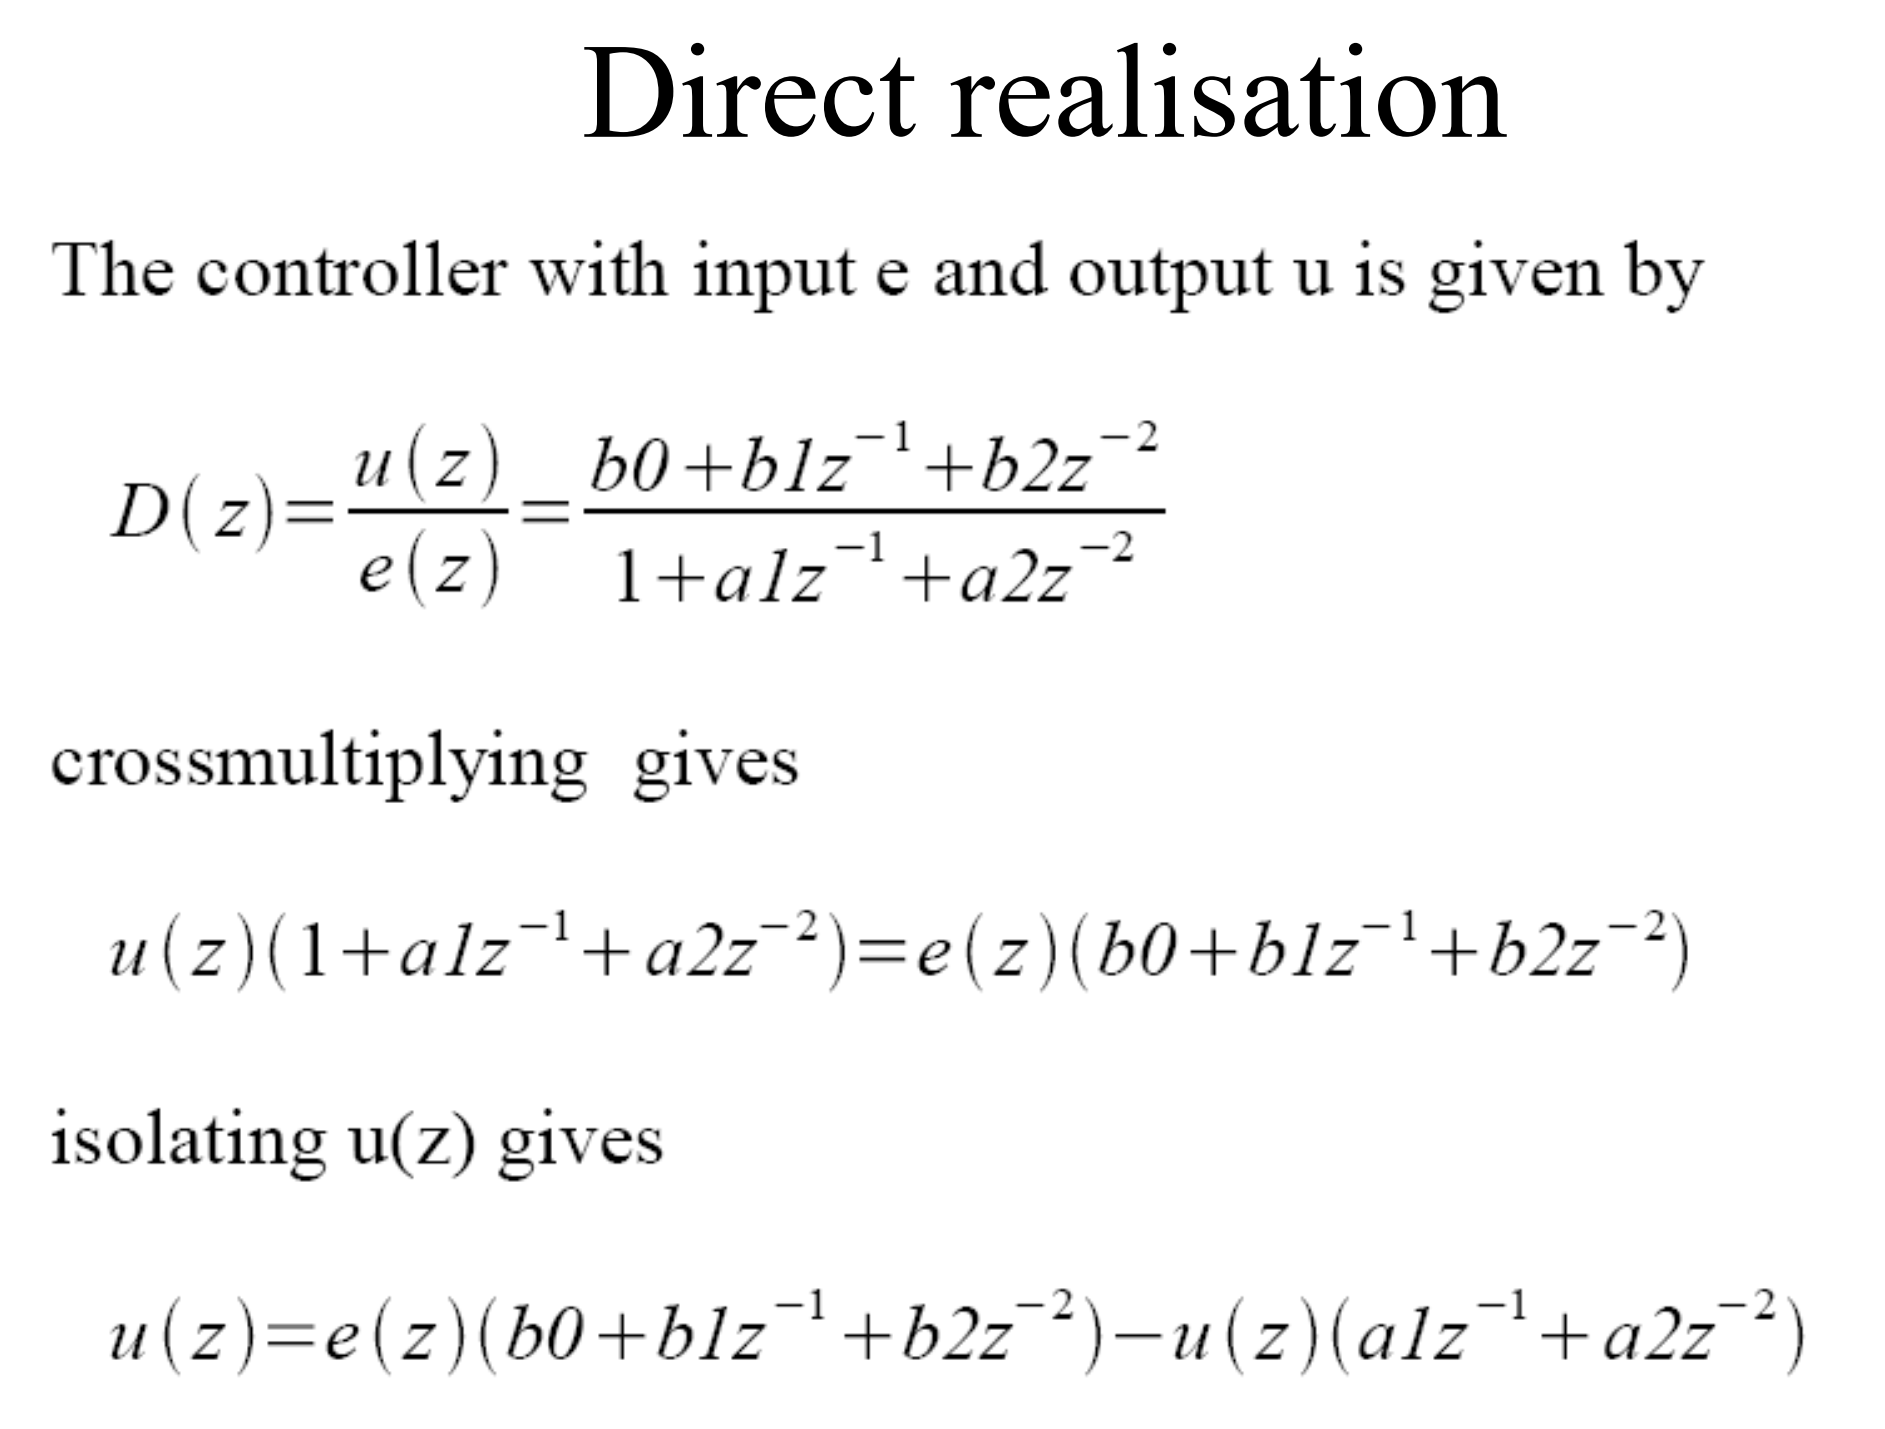

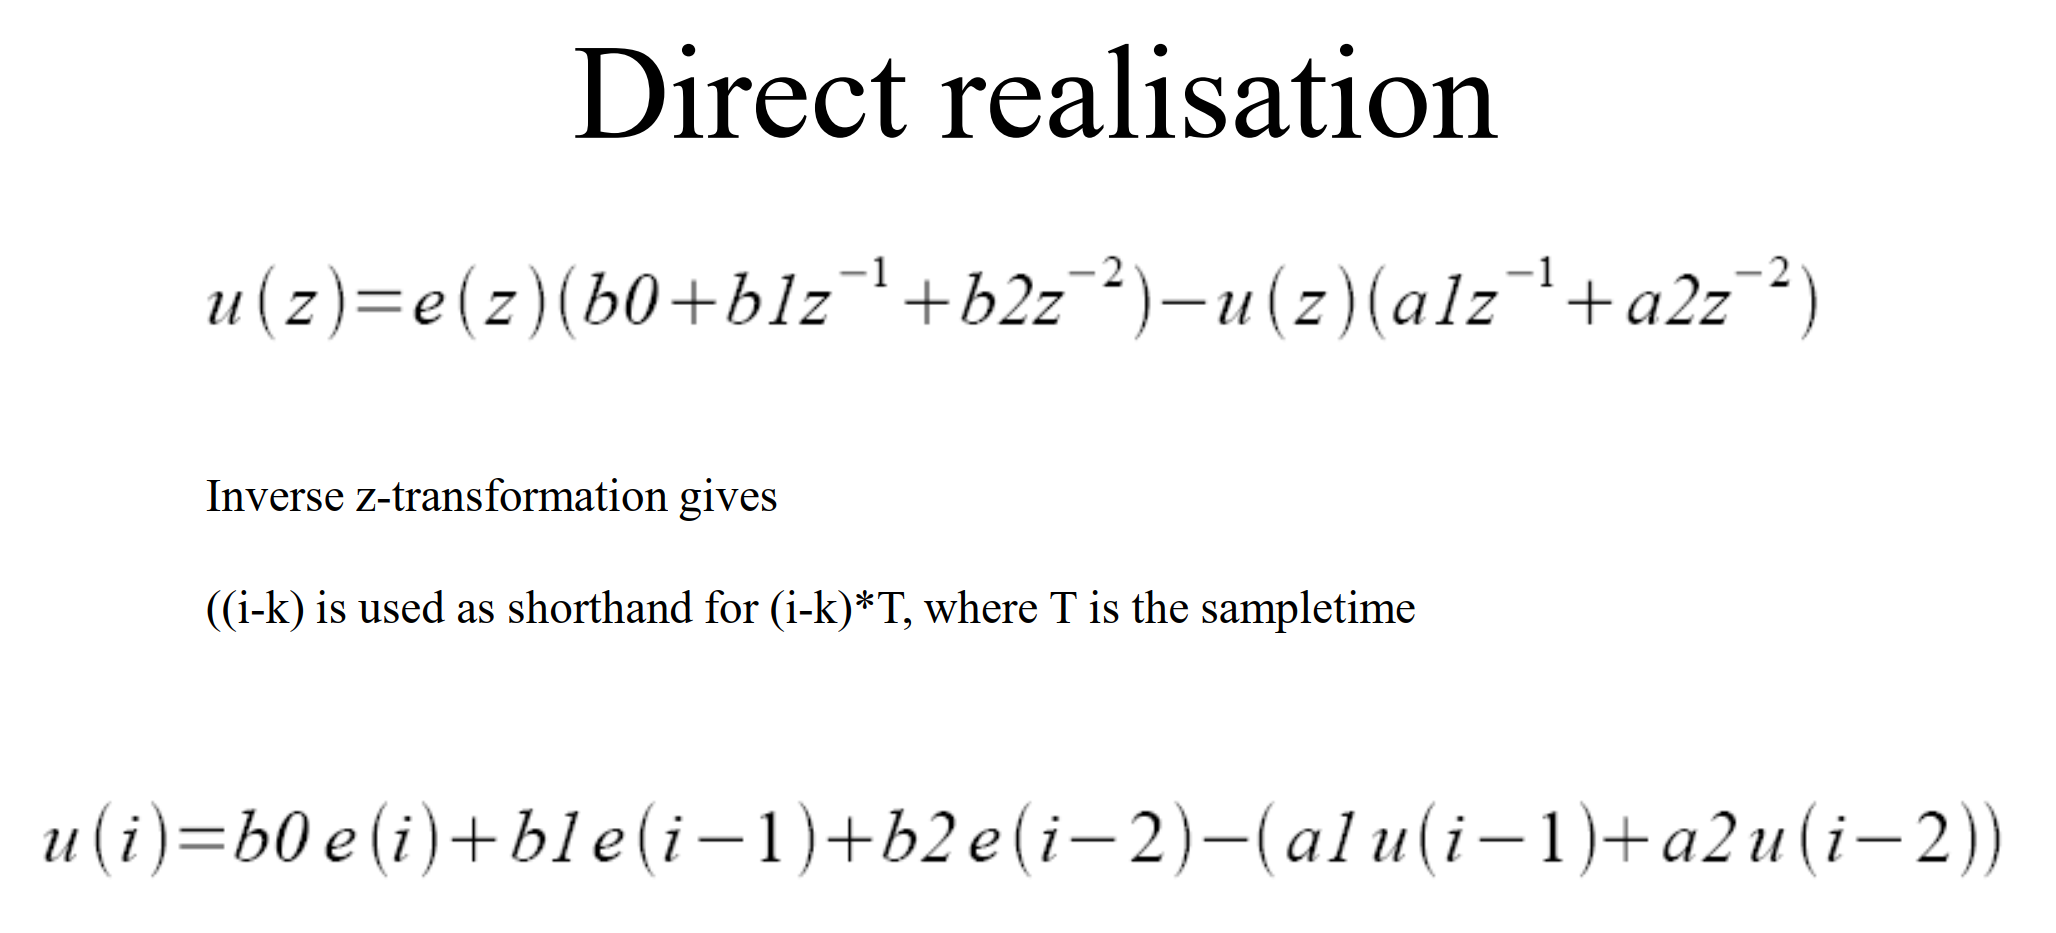


ts=4;  
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
x0 = [m10; m20; m30; m40];

u1_1=0.0;u1_2=0.0;u1_3=0.0;u1_4=0.0;u1_5=0.0;%输入向量 的初始状态，这里使用线性模型，与模型离散化后的传递函数的z阶次有关
u2_1=0.0;u2_2=0.0;u2_3=0.0;u2_4=0.0;u2_5=0.0;
y1_1=0.0;y1_2=0.0;y1_3=0.0;y1_4=0.0;y1_5=0.0%输出的初始状态

y1_5 = 0

y2_1=0.0;y2_2=0.0;y2_3=0.0;y2_4=0.0;y2_5=0.0%输出的初始状态

y2_5 = 0

[num_11,den_11]=tfdata(G_MIMO(1,1),'v')

num_11 =          0    0.0047   -0.0136    0.0132   -0.0043


den_11 =     1.0000   -3.8841    5.6572   -3.6621    0.8890


[num_12,den_12]=tfdata(G_MIMO(1,1),'v')

num_12 =          0    0.0047   -0.0136    0.0132   -0.0043


den_12 =     1.0000   -3.8841    5.6572   -3.6621    0.8890


[num_21,den_21]=tfdata(G_MIMO(1,1),'v')

num_21 =          0    0.0047   -0.0136    0.0132   -0.0043


den_21 =     1.0000   -3.8841    5.6572   -3.6621    0.8890


[num_22,den_22]=tfdata(G_MIMO(1,1),'v')

num_22 =          0    0.0047   -0.0136    0.0132   -0.0043


den_22 =     1.0000   -3.8841    5.6572   -3.6621    0.8890


x_pid=[0,0,0]';%PID的3个参数Kp Ki Kd组成的数组
error_1=0;%初始误差
t_final = 20*60; % [s] Final time
t = [t0:ts:t_final]'; % [s] Sample instants
N = length(t);

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;

for k=1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
    z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
    [u_pid,I]=MIMO_Decop_PID([0;0],y())
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
    u_50_F1(:,k),d(:,k),p);
    x(:,k+1) = Xk(end,:)';
    T = [T; Tk];
    X = [X; Xk];
end

for k=1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
    z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
    [u_pid,I]=MIMO_Decop_PID([0;0],y())
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
    u_50_F1(:,k),d(:,k),p);
    x(:,k+1) = Xk(end,:)';
    T = [T; Tk];
    X = [X; Xk];
end